# **IS501 NMTB HELMHOLTZ** **MAGNETIC TEST BED**

The University of Beihang conducted an extensive investigation for the design and construction of the magnetic testbed denominated IS501NMTB. According to [1], the primary objective of this testbed is to accurately reproduce Earth’s magnetic field along the satellites’ orbits and the prediction of Earth’s magnetic field throughout the orbit with the utilization of Helmholtz coils.

## 1.Helmholtz Coils (HC)

### 1.1. Magnetic Model on the spin axis

A pair of Square Helmholtz coils were used to generate a uniform magnetic field. In [1-3] it is explained that Helmholtz coils are constructed under the Biot-Savart law which is described as follows.

$\vec{B} = \frac{N \mu_0}{4\pi} \int \frac{I\vec{dL}\times\hat{r}}{r^2}$   (1.1)

Where:

$\vec{B}$ : Is the magnetic flux density (Tesla).

$\vec{dL}$: Is the differential of length in the direction of L (meter).

$r$: is the distance from the differential element to the point to be studied (meter).

$\hat{r}$: is the vector unit in vector direction $\hat{r}$.

$\mu_0$: Is the constant of magnetic permeability in vacuum with $\mu_0 = 4\pi E-7$(Tm/A).

$I$: is the intensity of the electric current in the conductor (Ampere).

$N$: Is the number of turns in the coil.

In our case, according to [1, 4] and [6] the Biot-Savart Law solution for one coil pairs that generates a magnetic flux evaluated in the $Z$ direction (Figure 1 ) is denoted by:

$\vec{B}(z) = \frac{2\mu_0 NIa^2}{\pi} \times \left[\frac{1}{\left(a^2+\left(z+\frac{h}{2}\right)^2\right) \left(2a^2+\left(z+\frac{h}{2}\right) ^2 \right)^{1/2}} + \frac{1}{\left(a^2+\left(z-\frac{h}{2}\right)^2\right) \left(2a^2+\left(z-\frac{h}{2}\right) ^2 \right)^{1/2}}\right] \hat{z}$  (1.2)

Where:

- L = Coil side lenght

- a = L/2

- h = distance between coils

- z = distance of evaluation from the separation center.

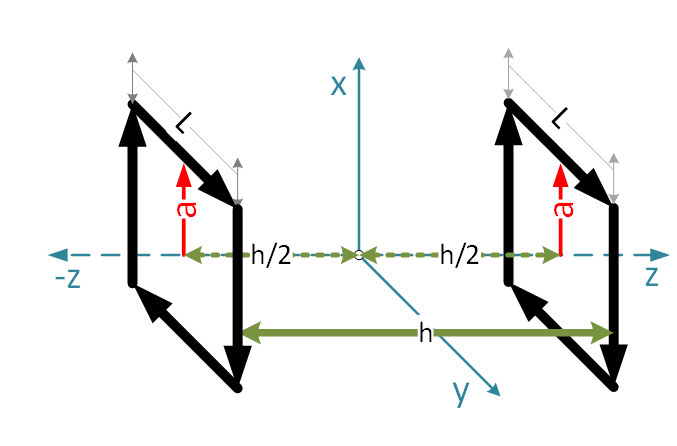

According to [1] the magnetic field in the $z=0$ is predicted by equation (1.3)

$\vec{B(0)} = \frac{4\mu_0NIa^2}{\pi}\left[\frac{1}{\left(a^2+\left(\frac{h}{2}\right)^2\right)\left(2a^2+\left(\frac{h}{2}\right)^2\right)^{1/2}}\right]$  (1.3)

The following line present an implementation with the equation (1.3)

If $h = a$ the $\vec{B(0)}$ is defined as:

$\vec{B(0)} = \frac{32}{15} \cdot \frac{\mu_0 NI}{\pi a}$ (1.4)

The following line present an implementation of the equation (1.4).

For equations (1.3) and (1.4) it can be noticed that the magnetic field in the center of the IS501NMTB has a linear relatioship with the current ($I$) and the generated magnetic field ($B$) . This is due to the square coil is symetric and all magnetic field components generated on  the coil plane are cancelled due ti its symmetry.

### 1.2. Magnetic Field generated in the 3D space

To perform accurate simulations in the 3D space it is necessary to review if the magnetic field has contribution on the other axis. Therefore, it is necessary to evaluate the magnetic field in a point that its not in the z axis. So in this part the Biot-Savart Law is solved under numerical methods. In this part, the equation (1.5) shows the Biot-Savart law as summatory. Equation (1.5) was based in the following figure. 

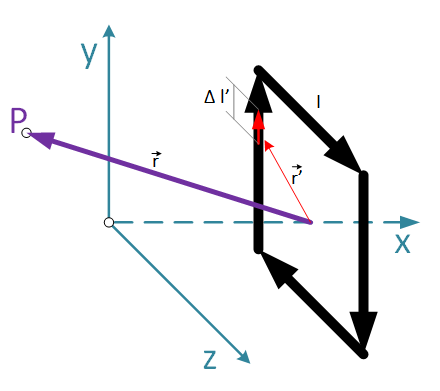

$\vec{B}(\vec{r}) = \frac{N \mu_0}{4\pi}\sum\frac{I'\Delta\vec{l'}\times(\vec{r}-\vec{r'})}{||\vec{r}-\vec{r'}||^3}$ (1.5)

A numerical aproximation for the equation (1.5) it is implemented using the file called:

### 1.2. Magnetic Coils Simulation

To perform simulations for the IS501NMTB, the geometrical parameters for each coil was taken of [1] and are listed below:

mu_0 = 4*pi*1e-7;                 %Magnetic Permeability of Vacuum

**For Z axis**

IS501NMTB.Z.L = 1.03;
IS501NMTB.Z.a = IS501NMTB.Z.L/2;
IS501NMTB.Z.h = 0.5 ;
%IS501NMTB.Z.N = 59.12;
IS501NMTB.Z.N = 20;
IS501NMTB.Z.R = 10.32;
IS501NMTB.Z.Lz = IS501NMTB.Z.N^2*(2^(1/2)*mu_0*IS501NMTB.Z.L^2)/(IS501NMTB.Z.a*pi);
IS501NMTB.Z.tau = IS501NMTB.Z.Lz/IS501NMTB.Z.R;

**For Y axis**

IS501NMTB.Y.L = 1.02;
IS501NMTB.Y.a = IS501NMTB.Y.L/2;
IS501NMTB.Y.h = 0.5;
%IS501NMTB.Y.N = 111.2; 
IS501NMTB.Y.N = 35;
IS501NMTB.Y.R = 7.61;
IS501NMTB.Y.Ly = IS501NMTB.Y.N^2*(2^(1/2)*mu_0*IS501NMTB.Y.L^2)/(IS501NMTB.Y.a*pi);
IS501NMTB.Y.tau = IS501NMTB.Y.Ly/IS501NMTB.Y.R;

**For X axis**

IS501NMTB.X.L = 1.03;
IS501NMTB.X.a = IS501NMTB.X.L/2 ;
IS501NMTB.X.h = 0.5;
%IS501NMTB.X.N = 97.18;
IS501NMTB.X.N = 36;
IS501NMTB.X.R = 14.84;
IS501NMTB.X.Lx = IS501NMTB.X.N^2*(2^(1/2)*mu_0*IS501NMTB.X.L^2)/(IS501NMTB.X.a*pi);
IS501NMTB.X.tau = IS501NMTB.X.Lx/IS501NMTB.X.R;

#### **1.2.1. Simulation for coils**

First, we will simulate the magnetic field generated by the Z coil, Y coil and X coil independently (one coil turn on) over the XY, XZ, and YZ plane with a current of 1A with the following code.

%helmzholtzSimulation
%%%Get results from previous simulations
%load('1dSimulatedData.mat');
load('1dSimulateData2.mat')

The following figure depicts the simulated distribution of the IS501 NMTB HELMHOLTZ MAGNETIC TEST BED implemented by beihang university.

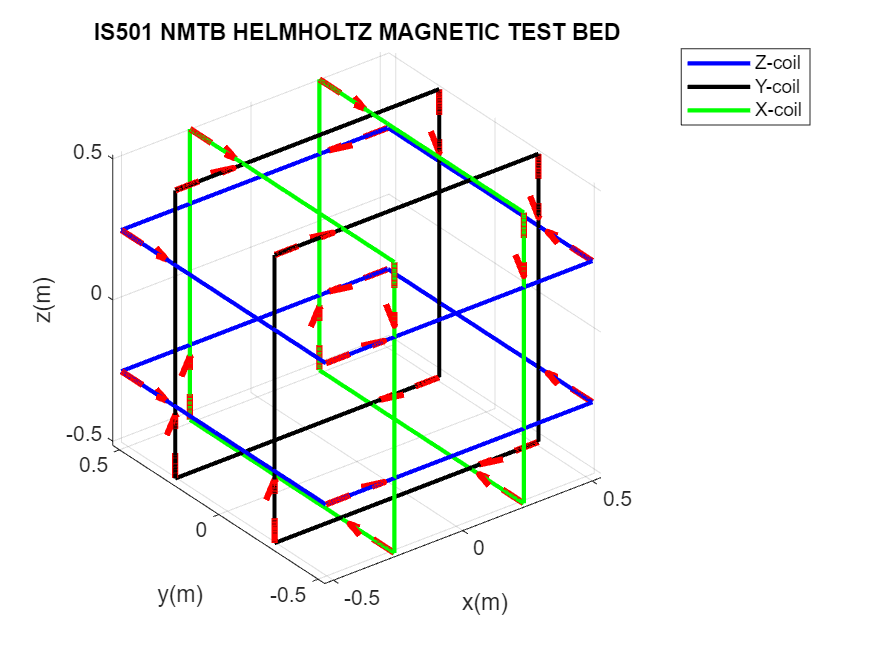

figure()
h1 = plotHeltholtsCoils(zcoil.spire1,zcoil.spire2,1,2,'b'); hold on;
h2 = plotHeltholtsCoils(ycoil.spire1,ycoil.spire2,1,2,'k');
h3 = plotHeltholtsCoils(xcoil.spire1,xcoil.spire2,1,2,'g');
legend([h1,h2,h3],'Z-coil','Y-coil','X-coil');
axis equal; xlabel('x(m)'); ylabel('y(m)'); zlabel('z(m)');
title('IS501 NMTB HELMHOLTZ MAGNETIC TEST BED');

**Simulation Analisys**

The results for the Z-coil simulation is saved in zcoil variable, the results in the Y-coil simulation is saved in the y coil variable and the results for the X-coil simulation is saved in .

With the following code we will analize which area are almost constant in the midle of the coil with an margin of 0.5% of variance.

tolerance = 0.005; %%%Tolerance of 0.5%

%%% Analize z coils (xy-plane)
max_Bz = max(zcoil.xy.norB, [], 'all');
permitedRangez = [1-tolerance, 1+tolerance] * max_Bz;  
[rowz, colz] = find(zcoil.xy.norB >= permitedRangez(1) & zcoil.xy.norB <= permitedRangez(2));
filteredValuesZ = zcoil.xy.norB(rowz, colz)*1E9;

%%% Analize y coils (xz-plane)
max_By = max(ycoil.xz.norB, [], 'all');
permitedRangey = [1-tolerance, 1+tolerance] * max_By;  
[rowy, coly] = find(ycoil.xz.norB >= permitedRangey(1) & ycoil.xz.norB <= permitedRangey(2));
filteredValuesY = ycoil.xz.norB(rowy, coly)*1E9;

%%% Analize x coils (yz-plane)
max_Bx = max(xcoil.yz.norB, [], 'all');
permitedRangex = [1-tolerance, 1+tolerance] * max_Bx;  
[rowx, colx] = find(xcoil.yz.norB >= permitedRangex(1) & xcoil.yz.norB <= permitedRangex(2));
filteredValuesX = xcoil.yz.norB(rowx, colx)*1E9;

Finally, we generate the figure to see the magnitude of the generated magnetic field

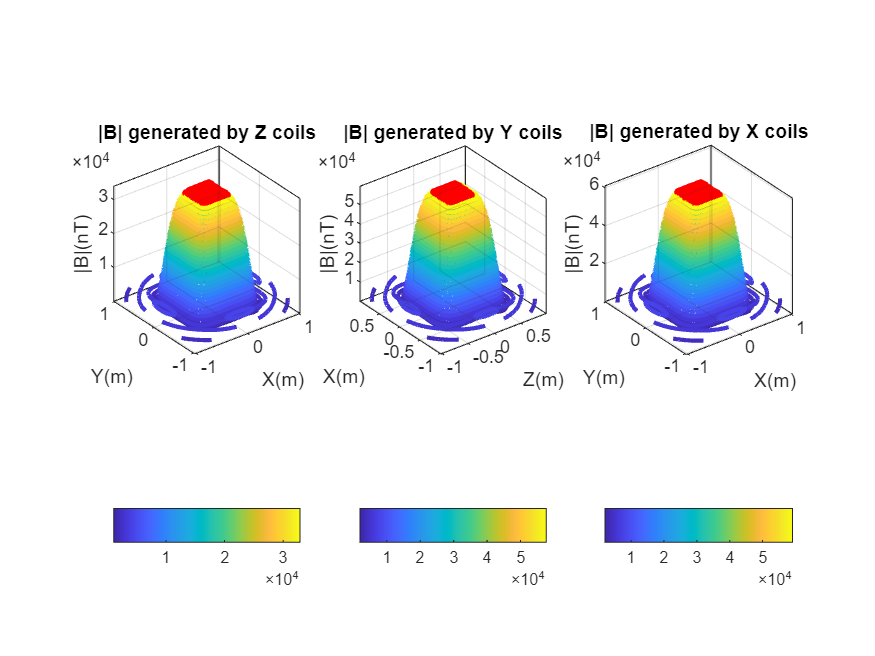

figure()
subplot(1,3,1)
    contour3(zcoil.xy.X, zcoil.xy.Y, zcoil.xy.norB*1E9,30,'LineWidth',2); hold on; grid on;
    plot3(zcoil.xy.X(rowz, colz),zcoil.xy.Y(rowz, colz),filteredValuesZ,'.','Color','r','MarkerSize',11);
    xlabel('X(m)'); ylabel('Y(m)'); zlabel('|B|(nT)');
    axis vis3d; %view([0 90]);   
    title('|B| generated by Z coils'); axis vis3d; colorbar('southoutside');
subplot(1,3,2)
    contour3(ycoil.xz.Z, ycoil.xz.X,ycoil.xz.norB*1E9,30,'LineWidth',2); hold on; grid on;
    plot3(ycoil.xz.Z(rowy, coly),ycoil.xz.X(rowy, coly),filteredValuesY,'.','Color','r','MarkerSize',11);
    xlabel('Z(m)'); ylabel('X(m)'); zlabel('|B|(nT)');
    axis vis3d; %view([0 90]); 
    title('|B| generated by Y coils');axis vis3d; colorbar('southoutside');
subplot(1,3,3)
    contour3(xcoil.yz.Y, xcoil.yz.Z, xcoil.yz.norB*1E9,30,'LineWidth',2); hold on; grid on;
    plot3(xcoil.yz.Y(rowx, colx), xcoil.yz.Z(rowx, colx),filteredValuesX,'.','Color','r','MarkerSize',11);
    xlabel('X(m)'); ylabel('Y(m)'); zlabel('|B|(nT)');
    axis vis3d; %view([0 90]); 
    title('|B| generated by X coils'); axis vis3d; colorbar('southoutside');

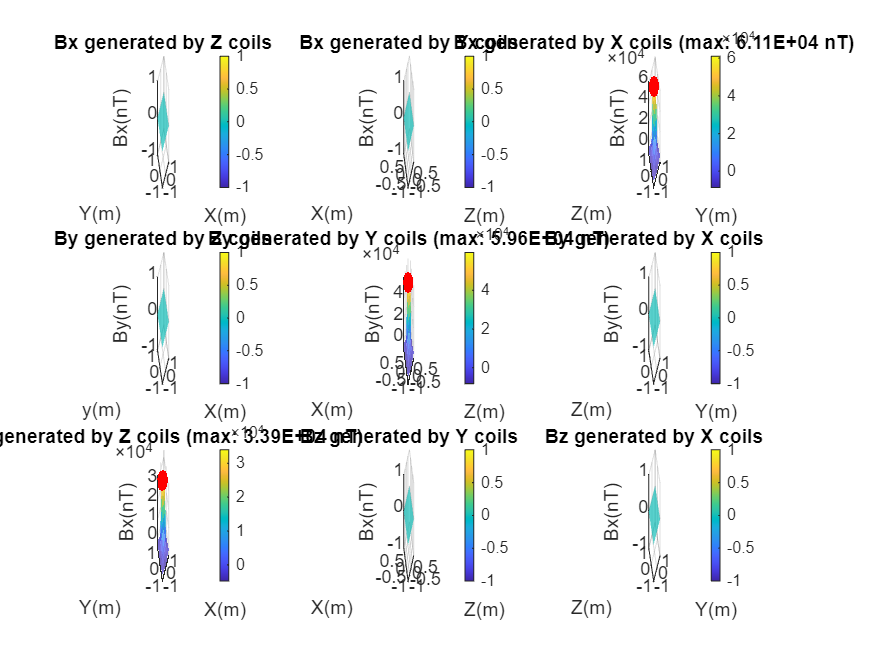

scale = 1E9; %to nT
figure()
subplot(3,3,1)
    surf(zcoil.xy.X, zcoil.xy.Y, zcoil.xy.Bx*scale,'EdgeColor','none','FaceAlpha', 0.7);grid on; hold on;
    xlabel('X(m)'); ylabel('Y(m)'); zlabel('Bx(nT)');
    title('Bx generated by Z coils'); colorbar;
subplot(3,3,2)
    surf(ycoil.xz.Z, ycoil.xz.X, ycoil.xz.Bx*scale,'EdgeColor','none','FaceAlpha', 0.7);grid on; hold on;
    xlabel('Z(m)'); ylabel('X(m)'); zlabel('Bx(nT)');
    title('Bx generated by Y coils'); colorbar;
subplot(3,3,3)
    surf(xcoil.yz.Y, xcoil.yz.Z, xcoil.yz.Bx*scale,'EdgeColor','none','FaceAlpha', 0.7);grid on; hold on;
    plot3(xcoil.yz.Y(rowx, colx),xcoil.yz.Z(rowx, colx),filteredValuesX,'.','Color','r','MarkerSize',11);
    xlabel('Y(m)'); ylabel('Z(m)'); zlabel('Bx(nT)');
    title(['Bx generated by X coils (max: ', num2str(max_Bx*scale,'%2.2E'), ' nT)']); colorbar;
    
subplot(3,3,4)
    surf(zcoil.xy.X, zcoil.xy.Y, zcoil.xy.By*scale,'EdgeColor','none','FaceAlpha', 0.7);grid on; hold on;
    xlabel('X(m)'); ylabel('y(m)'); zlabel('By(nT)');
    title('By generated by Z coils'); colorbar;
subplot(3,3,5)
    surf(ycoil.xz.Z, ycoil.xz.X, ycoil.xz.By*scale,'EdgeColor','none','FaceAlpha', 0.7);grid on; hold on;
    plot3(ycoil.xz.Z(rowy, coly), ycoil.xz.X(rowy, coly), filteredValuesY,'.','Color','r','MarkerSize',11);
    xlabel('Z(m)'); ylabel('X(m)'); zlabel('By(nT)');
    title(['By generated by Y coils (max: ', num2str(max_By*scale,'%2.2E'), ' nT)']); colorbar;
subplot(3,3,6)
    surf(xcoil.yz.Y, xcoil.yz.Z, xcoil.yz.By*scale,'EdgeColor','none','FaceAlpha', 0.7);grid on; hold on;
    xlabel('Y(m)'); ylabel('Z(m)'); zlabel('By(nT)');
    title('By generated by X coils'); colorbar;

subplot(3,3,7)
    surf(zcoil.xy.X, zcoil.xy.Y, zcoil.xy.Bz*scale,'EdgeColor','none','FaceAlpha', 0.7);grid on; hold on;
    plot3(zcoil.xy.X(rowz, colz),zcoil.xy.Y(rowz, colz),filteredValuesZ,'.','Color','r','MarkerSize',11);
    xlabel('X(m)'); ylabel('Y(m)'); zlabel('Bx(nT)');
    title(['Bz generated by Z coils (max: ', num2str(max_Bz*scale,'%2.2E'), ' nT)']); colorbar;
subplot(3,3,8)
    surf(ycoil.xz.Z, ycoil.xz.X, ycoil.xz.Bz*scale,'EdgeColor','none','FaceAlpha', 0.7);grid on; hold on;
    xlabel('Z(m)'); ylabel('X(m)'); zlabel('Bx(nT)');
    title('Bz generated by Y coils'); colorbar; 
subplot(3,3,9)
    surf(xcoil.yz.Y, xcoil.yz.Z, xcoil.yz.Bz*scale,'EdgeColor','none','FaceAlpha', 0.7);grid on; hold on;
    xlabel('Y(m)'); ylabel('Z(m)'); zlabel('Bx(nT)');
    title('Bz generated by X coils'); colorbar;

Then, we will show the magnetic field in the longitudinal plane generated by coil z, y and x with a current of 1A.

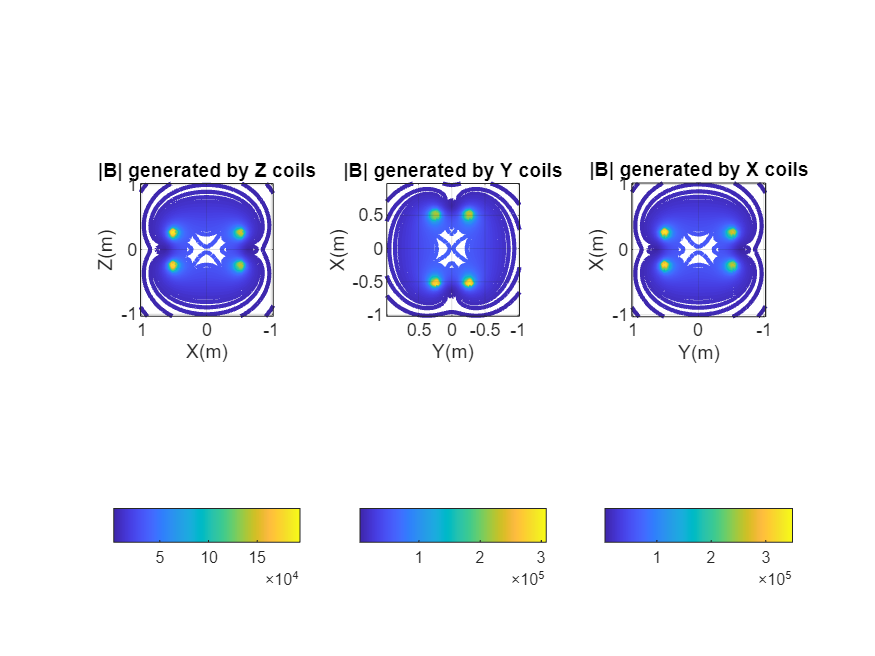

figure()
subplot(1,3,1)
    contour3(zcoil.xz.Z, zcoil.xz.X, zcoil.xz.norB*1E9,100,'LineWidth',2);
    grid on; xlabel('Z(m)'); ylabel('X(m)'); zlabel('B(nT)');
    title('|B| generated by Z coils');axis vis3d;
    view([-90 90]); colorbar('southoutside');
subplot(1,3,2)
    contour3(ycoil.xy.X, ycoil.xy.Y, ycoil.xy.norB*1E9,100,'LineWidth',2);
    grid on; xlabel('X(m)'); ylabel('Y(m)'); zlabel('B(nT)');
    title('|B| generated by Y coils');axis vis3d; 
    view([-90 90]); colorbar('southoutside')
subplot(1,3,3)
    contour3(xcoil.xy.X, xcoil.xy.Y, xcoil.xy.norB*1E9,100,'LineWidth',2);
    grid on; xlabel('X(m)'); ylabel('Y(m)'); zlabel('B(nT)');
    title('|B| generated by X coils');axis vis3d; 
    view([-90 90]); colorbar('southoutside')

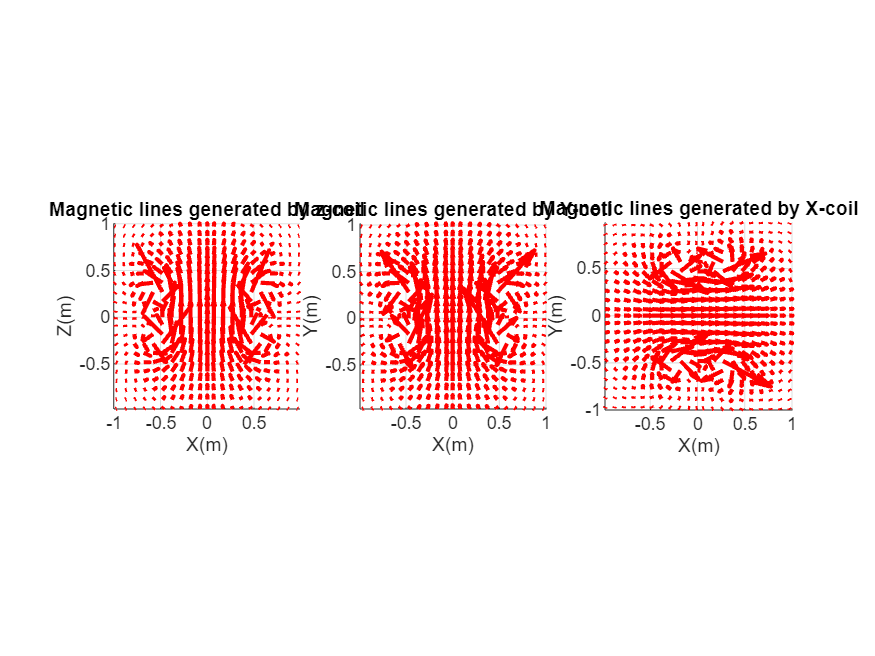

figure    
subplot(1,3,1)
    maxB = max(zcoil.xz.norB(:));
    for i = 1:length(zcoil.xz.X)
        for j = 1:length(zcoil.xz.Z)
            if (mod(i,2)==0)&&(mod(j,2)==0)
                [h1,~] = plotVector([zcoil.xz.X(i,j),0,zcoil.xz.Z(i,j)],[zcoil.xz.Bx(i,j),zcoil.xz.By(i,j),zcoil.xz.Bz(i,j)]/maxB,1 ,'r-',' ','m');hold on;
                set(h1,'LineWidth',2,'MaxHeadSize',2);
            end
        end
    end
    view([0 0]);
    title('Magnetic lines generated by z-coil')
    grid on; xlabel('X(m)'); ylabel('Y(m)'); zlabel('Z(m)');axis vis3d;

subplot(1,3,2)
    maxB = max(ycoil.xy.norB(:));
    for i = 1:length(ycoil.xy.X)
        for j = 1:length(ycoil.xy.Y)
            if (mod(i,2)==0)&&(mod(j,2)==0)
                [h1,~] = plotVector([ycoil.xy.X(i,j),ycoil.xy.Y(i,j),0],[ycoil.xy.Bx(i,j),ycoil.xy.By(i,j),ycoil.xy.Bz(i,j)]/maxB,1 ,'r-',' ','m');hold on;
                set(h1,'LineWidth',2,'MaxHeadSize',2);
            end
        end
    end
    view([0 90]);
    title('Magnetic lines generated by Y-coil')
    grid on; xlabel('X(m)'); ylabel('Y(m)'); zlabel('Z(m)');axis vis3d;

subplot(1,3,3)
    maxB = max(xcoil.xy.norB(:));
    for i = 1:length(xcoil.xy.X)
        for j = 1:length(xcoil.xy.Y)
            if (mod(i,2)==0)&&(mod(j,2)==0)
                [h1,~] = plotVector([xcoil.xy.X(i,j),xcoil.xy.Y(i,j),0],[xcoil.xy.Bx(i,j),xcoil.xy.By(i,j),xcoil.xy.Bz(i,j)]/maxB,1 ,'r-',' ','m');hold on;
                set(h1,'LineWidth',2,'MaxHeadSize',2);
            end
        end
    end
    view([0 90]);
    title('Magnetic lines generated by X-coil')
    grid on; xlabel('X(m)'); ylabel('Y(m)'); zlabel('Z(m)');axis vis3d;

In this simulation we can see that the generated magnetic field is almost constant over the spin axis and in the X-Y plane with a radius of 20cm. The magnetic field over the $Z-axis$ can be generated by the equation (1.2) . And the value of the magnetic Field in the $Z = 0$, $Y=0$ and $Z=0$ is calculated by equation (1.3). The magnetic field magnitude in the $z-axis$ is simulated and diplayed in the following figure. 

mu_0 = 4*pi*1e-7;    % Permeability in the vacum
functBxyz0 = @(N,I,a,h) (4 * mu_0 * N *I * a^2) / (pi) * (1/((a^2 + (h/2)^2) * (2 * a^2 + (h/2)^2)^(1/2)));

%%% Calculate the Bxyz in zCoil
By0_z = functBxyz0(IS501NMTB.Z.N,1,IS501NMTB.Z.a,IS501NMTB.Z.h);
fprintf('The magnetic field in Z = 0 m is: %E nT',By0_z*1E9);

The magnetic field in Z = 0 m is: 3.363147E+04 nT

%%% Calculate the Bxyz in yCoil
By0_y = functBxyz0(IS501NMTB.Y.N,1,IS501NMTB.Y.a,IS501NMTB.Y.h);
fprintf('The magnetic field in Y = 0 m is: %E nT',By0_y*1E9);

The magnetic field in Y = 0 m is: 5.914820E+04 nT

%%% Calculate the Bxyz in xCoil
By0_x = functBxyz0(IS501NMTB.X.N,1,IS501NMTB.X.a,IS501NMTB.X.h);
fprintf('The magnetic field in X = 0 m is: %E nT',By0_x*1E9);

The magnetic field in X = 0 m is: 6.053664E+04 nT

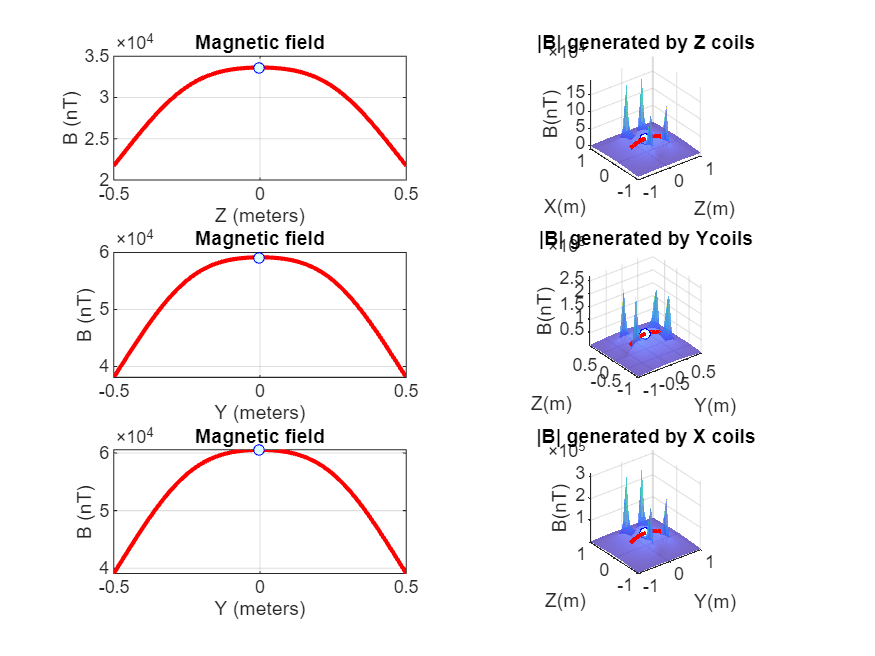

figure()
subplot(3,2,1)
    [Bzz,~,z] = biotSavartPlot(IS501NMTB.Z, 1, length(zcoil.xz.X), 'Z', 'r-'); hold on;
    plot(0,By0_z*1E9,'bo', 'MarkerSize', 5, 'MarkerFaceColor', '#D9FFFF')
subplot(3,2,2)
     surf(zcoil.xz.Z, zcoil.xz.X, zcoil.xz.norB*1E9,'EdgeColor','none','FaceAlpha', 0.7); hold on;
     plot3(z,zeros(1,length(zcoil.xz.X)),Bzz*1E9,'r','LineWidth',2);
     plot3(0,0,By0_z*1E9,'bo','MarkerSize',5,'MarkerFaceColor','#D9FFFF');
     grid on; xlabel('Z(m)'); ylabel('X(m)'); zlabel('B(nT)');
     title('|B| generated by Z coils');axis vis3d;
    
subplot(3,2,3)
    [Byy,~,y] = biotSavartPlot(IS501NMTB.Y, 1, length(ycoil.xy.X), 'Y', 'r-'); hold on;
    plot(0,By0_y*1E9,'bo', 'MarkerSize', 5, 'MarkerFaceColor', '#D9FFFF');
subplot(3,2,4)
     surf(ycoil.xy.X, ycoil.xy.Y, ycoil.xy.norB*1E9,'EdgeColor','none','FaceAlpha', 0.7); hold on;
     plot3(y,zeros(1,length(ycoil.xy.X)),Byy*1E9,'r','LineWidth',2);
     plot3(0,0,By0_y*1E9,'bo','MarkerSize',5,'MarkerFaceColor','#D9FFFF');
     grid on; xlabel('Y(m)'); ylabel('Z(m)'); zlabel('B(nT)');
     title('|B| generated by Ycoils');axis vis3d;

subplot(3,2,5)
    [Bxx,~,x] = biotSavartPlot(IS501NMTB.X, 1, length(xcoil.xy.X), 'Y', 'r-'); hold on;
    plot(0,By0_x*1E9,'bo', 'MarkerSize', 5, 'MarkerFaceColor', '#D9FFFF');
subplot(3,2,6)
     surf(xcoil.xy.X, xcoil.xy.Y, xcoil.xy.norB*1E9,'EdgeColor','none','FaceAlpha', 0.7); hold on;
     plot3(x,zeros(1,length(xcoil.xy.X)),Bxx*1E9,'r','LineWidth',2);
     plot3(0,0,By0_x*1E9,'bo','MarkerSize',5,'MarkerFaceColor','#D9FFFF');
     grid on; xlabel('Y(m)'); ylabel('Z(m)'); zlabel('B(nT)');
     title('|B| generated by X coils');axis vis3d;

The magnetic field generated from a Helmholtz Pair is uniform over a relatively large region of space; This space is considered spherical whose center is at the midpoint of the segment that joins the centers of the coils, and the radius measurement is of the order of half the radius of the coils [5]. The above simulations are according with this affirmation due to the generated magnetic field generated at the center of the magnetic chamber are homogeneous within a radius of 20 cm and.

clearvars -except IS501NMTB xcoil ycoil zcoil

## **2. Analize Measured Data**

Analize data measured 2/08/2001

%%% Read data measured from previous tests
fileName_x_jhonny = 'data_2014/A_FUNCION_TRANSFERENCIA_X.mat'; 
fileName_y_jhonny = 'data_2014/A_FUNCION_TRANSFERENCIA_Y.mat'; 
fileName_z_jhonny = 'data_2014/A_FUNCION_TRANSFERENCIA_Z.mat';
load(fileName_x_jhonny); load(fileName_y_jhonny); load(fileName_z_jhonny);
jhonny.xcoil = readProcessData_jhonny(TRANSFERENCIA_X,1,-1);
jhonny.ycoil = readProcessData_jhonny(TRANSFERENCIA_Y,1,-1);
jhonny.zcoil = readProcessData_jhonny(TRANSFERENCIA_Z,1,-1);
%%%Clear unused data
clear TRANSFERENCIA_X TRANSFERENCIA_Y TRANSFERENCIA_Z fileName_x_jhonny fileName_y_jhonny fileName_z_jhonny

%%%Perform linear correlation for magnetic field
degree_of_polynomial = 1;
jhonny.coeffsB.x = polyfit(jhonny.xcoil.I, jhonny.xcoil.B , degree_of_polynomial);
jhonny.coeffsB.y = polyfit(jhonny.ycoil.I, jhonny.ycoil.B , degree_of_polynomial);
jhonny.coeffsB.z = polyfit(jhonny.zcoil.I, jhonny.zcoil.B , degree_of_polynomial);

%%%create curves with the measured values
jhonny.fitB.x = polyval(jhonny.coeffsB.x, jhonny.xcoil.I); % Calculate fitted y values
jhonny.ecuacion_regresionB.x = sprintf('y = %.2fx + %.2f',jhonny.coeffsB.x(1), jhonny.coeffsB.x(2));
%%create curves with the measured values
jhonny.fitB.y = polyval(jhonny.coeffsB.y, jhonny.ycoil.I); % Calculate fitted y values
jhonny.ecuacion_regresionB.y = sprintf('y = %.2fx + %.2f',jhonny.coeffsB.y(1), jhonny.coeffsB.y(2));
%%create curves with the measured values
jhonny.fitB.z = polyval(jhonny.coeffsB.z, jhonny.zcoil.I); % Calculate fitted y values
jhonny.ecuacion_regresionB.z = sprintf('y = %.2fx + %.2f',jhonny.coeffsB.z(1), jhonny.coeffsB.z(2));

%%%Perform linear correlation for resistance
degree_of_polynomial = 1;
jhonny.coeffsRes.x = polyfit(jhonny.xcoil.I, jhonny.xcoil.V , degree_of_polynomial);
jhonny.coeffsRes.y = polyfit(jhonny.ycoil.I, jhonny.ycoil.V , degree_of_polynomial);
jhonny.coeffsRes.z = polyfit(jhonny.zcoil.I, jhonny.zcoil.V , degree_of_polynomial);

%%%create curves with the measured values
jhonny.fitRes.x = polyval(jhonny.coeffsRes.x, jhonny.xcoil.I); % Calculate fitted y values
jhonny.ecuacion_regresionRes.x = sprintf('y = %.2fx + %.2f',jhonny.coeffsRes.x(1), jhonny.coeffsRes.x(2));
%%create curves with the measured values
jhonny.fitRes.y = polyval(jhonny.coeffsRes.y, jhonny.ycoil.I); % Calculate fitted y values
jhonny.ecuacion_regresionRes.y = sprintf('y = %.2fx + %.2f',jhonny.coeffsRes.y(1), jhonny.coeffsRes.y(2));
%%create curves with the measured values
jhonny.fitRes.z = polyval(jhonny.coeffsRes.z, jhonny.zcoil.I); % Calculate fitted y values
jhonny.ecuacion_regresionRes.z = sprintf('y = %.2fx + %.2f',jhonny.coeffsRes.z(1), jhonny.coeffsRes.z(2));

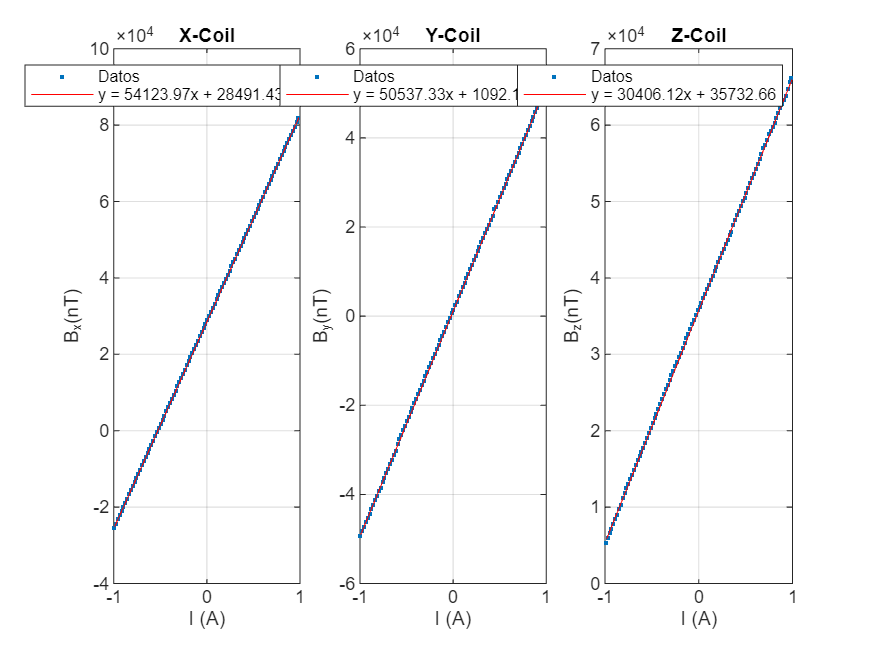

%%%Plot results
figure()
subplot(1,3,1)
    plot(jhonny.xcoil.I,jhonny.xcoil.B,'.'); hold on;
    plot(jhonny.xcoil.I,jhonny.fitB.x,'r-'); legend('Datos', jhonny.ecuacion_regresionB.x);
    xlabel('I (A)'); ylabel('B_x(nT)'); grid on; title('X-Coil');
subplot(1,3,2)
    plot(jhonny.ycoil.I,jhonny.ycoil.B,'.'); hold on;
    plot(jhonny.ycoil.I,jhonny.fitB.y,'r-'); legend('Datos', jhonny.ecuacion_regresionB.y);
    xlabel('I (A)'); ylabel('B_y(nT)'); grid on; title('Y-Coil');
subplot(1,3,3)
    plot(jhonny.zcoil.I,jhonny.zcoil.B,'.'); hold on;
    plot(jhonny.zcoil.I,jhonny.fitB.z,'r-'); legend('Datos', jhonny.ecuacion_regresionB.z);
    xlabel('I (A)'); ylabel('B_z(nT)'); grid on; title('Z-Coil');

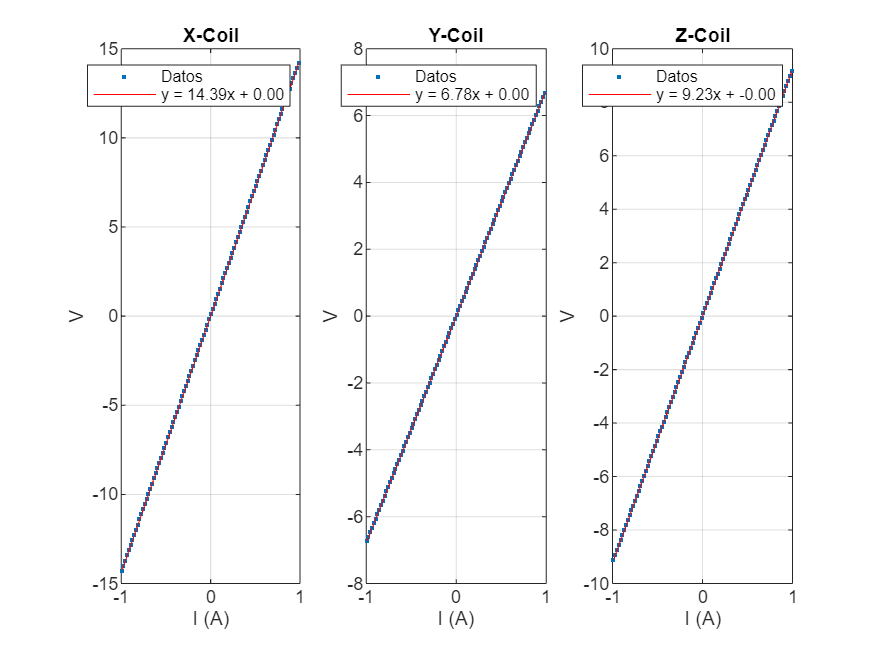

 figure()
subplot(1,3,1)
    plot(jhonny.xcoil.I,jhonny.xcoil.V,'.'); hold on;
    plot(jhonny.xcoil.I,jhonny.fitRes.x,'r-'); legend('Datos', jhonny.ecuacion_regresionRes.x);
    xlabel('I (A)'); ylabel('V'); grid on; title('X-Coil');
subplot(1,3,2)
    plot(jhonny.ycoil.I,jhonny.ycoil.V,'.'); hold on;
    plot(jhonny.ycoil.I,jhonny.fitRes.y,'r-'); legend('Datos', jhonny.ecuacion_regresionRes.y);
    xlabel('I (A)'); ylabel('V'); grid on; title('Y-Coil');
subplot(1,3,3)
    plot(jhonny.zcoil.I,jhonny.zcoil.V,'.'); hold on;
    plot(jhonny.zcoil.I,jhonny.fitRes.z,'r-'); legend('Datos', jhonny.ecuacion_regresionRes.z);
    xlabel('I (A)'); ylabel('V'); grid on; title('Z-Coil');

    clearvars -except IS501NMTB xcoil ycoil zcoil jhonny

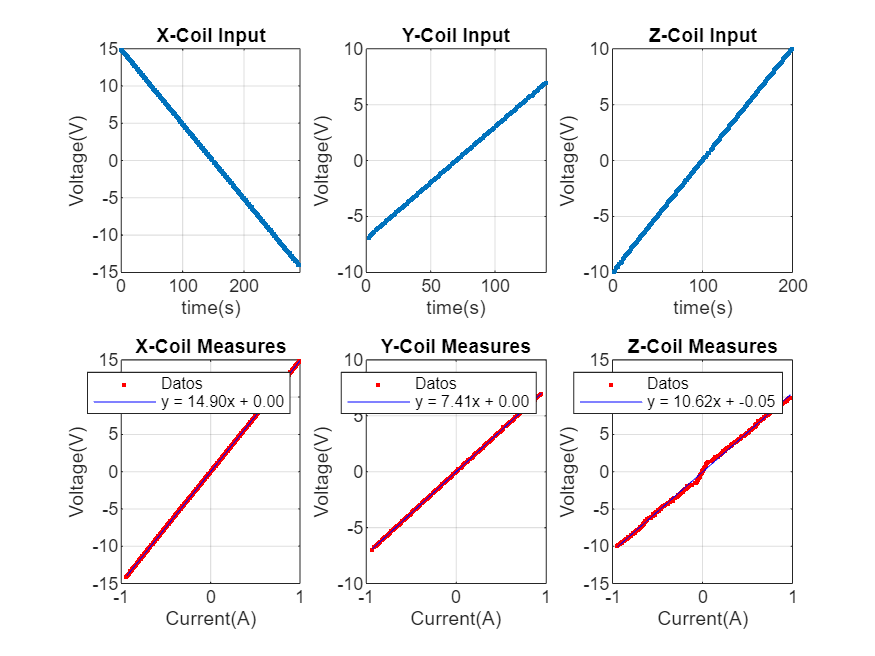

%%% Read data measured from previous tests
fileName_x = 'data_20240114/xCoil_Epoch_2024_01_14_t1.mat'; 
fileName_y = 'data_20240114/y_coil18012024.mat'; 
fileName_z = 'data_20240114/z_coil18012024.mat';
load(fileName_x); load(fileName_y); load(fileName_z);

%%% Interpretate and Clean Data
measuredData.xcoil = readProcessData(x_coil_data);
measuredData.ycoil = readProcessData(y_coil_data);
measuredData.zcoil = readProcessData(z_coil_data);

%%%Clear unused data
clear x_coil_data y_coil_data z_coil_data fileName_x fileName_y fileName_z

%%%Perform linear regression of degree 1 (a straight line)
degree_of_polynomial = 1;
coeffs_x = polyfit(measuredData.xcoil.I, measuredData.xcoil.V , degree_of_polynomial);
coeffs_y = polyfit(measuredData.ycoil.I, measuredData.ycoil.V , degree_of_polynomial);
coeffs_z = polyfit(measuredData.zcoil.I, measuredData.zcoil.V , degree_of_polynomial);

%%create curves with the measured values
y_fit_x = polyval(coeffs_x, measuredData.xcoil.I); % Calculate fitted y values
ecuacion_regresion_x = sprintf('y = %.2fx + %.2f',coeffs_x(1), coeffs_x(2));
%%create curves with the measured values
y_fit_y = polyval(coeffs_y, measuredData.ycoil.I); % Calculate fitted y values
ecuacion_regresion_y = sprintf('y = %.2fx + %.2f',coeffs_y(1), coeffs_y(2));
%%create curves with the measured values
y_fit_z = polyval(coeffs_z, measuredData.zcoil.I); % Calculate fitted y values
ecuacion_regresion_z = sprintf('y = %.2fx + %.2f',coeffs_z(1), coeffs_z(2));

%%%Plot the data and the linear regression line
figure()
subplot(2,3,1)
    plot(measuredData.xcoil.time,measuredData.xcoil.V,'.','LineWidth',3);hold on;
    xlabel('time(s)'); ylabel('Voltage(V)'); grid on; title('X-Coil Input');
subplot(2,3,2)
    plot(measuredData.ycoil.time,measuredData.ycoil.V,'.','LineWidth',3);hold on;
    xlabel('time(s)'); ylabel('Voltage(V)'); grid on; title('Y-Coil Input');
subplot(2,3,3)
    plot(measuredData.zcoil.time,measuredData.zcoil.V,'.','LineWidth',3);hold on;
    xlabel('time(s)'); ylabel('Voltage(V)'); grid on; title('Z-Coil Input');
    
subplot(2,3,4)
    plot(measuredData.xcoil.I, measuredData.xcoil.V,'r.','LineWidth',3);hold on;
    plot(measuredData.xcoil.I, y_fit_x, 'b-');
    ylabel('Voltage(V)'); xlabel('Current(A)'); grid on; title('X-Coil Measures')
    legend('Datos', ecuacion_regresion_x);
subplot(2,3,5)
    plot(measuredData.ycoil.I, measuredData.ycoil.V,'r.','LineWidth',3);hold on;
    plot(measuredData.ycoil.I, y_fit_y, 'b-');
    ylabel('Voltage(V)'); xlabel('Current(A)'); grid on; title('Y-Coil Measures')
    legend('Datos', ecuacion_regresion_y);
subplot(2,3,6)
    plot(measuredData.zcoil.I, measuredData.zcoil.V,'r.','LineWidth',3);hold on;
    plot(measuredData.zcoil.I, y_fit_z, 'b-');
    ylabel('Voltage(V)'); xlabel('Current(A)'); grid on; title('Z-Coil Measures')
    legend('Datos', ecuacion_regresion_z);

Compare data of 2021 and 2024

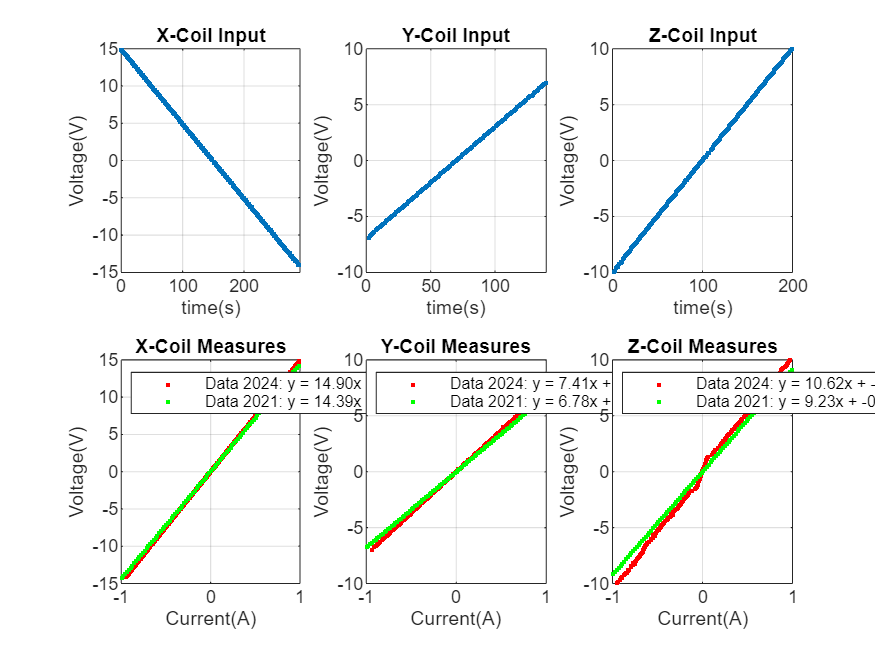

    %%%Plot the data and the linear regression line
figure()
subplot(2,3,1)
    plot(measuredData.xcoil.time,measuredData.xcoil.V,'.','LineWidth',3);hold on;
    xlabel('time(s)'); ylabel('Voltage(V)'); grid on; title('X-Coil Input');
subplot(2,3,2)
    plot(measuredData.ycoil.time,measuredData.ycoil.V,'.','LineWidth',3);hold on;
    xlabel('time(s)'); ylabel('Voltage(V)'); grid on; title('Y-Coil Input');
subplot(2,3,3)
    plot(measuredData.zcoil.time,measuredData.zcoil.V,'.','LineWidth',3);hold on;
    xlabel('time(s)'); ylabel('Voltage(V)'); grid on; title('Z-Coil Input');
    
subplot(2,3,4)
    plot(measuredData.xcoil.I, measuredData.xcoil.V,'r.','LineWidth',3);hold on;
    plot(jhonny.xcoil.I,jhonny.xcoil.V,'g.'); 
    %plot(measuredData.xcoil.I, y_fit_x, 'b--');
    ylabel('Voltage(V)'); xlabel('Current(A)'); grid on; title('X-Coil Measures')
    %legend('Data 2024','Data 2021', ecuacion_regresion_x);
    legend(['Data 2024: ', ecuacion_regresion_x],['Data 2021: ', jhonny.ecuacion_regresionRes.x],'Location','northwest');
subplot(2,3,5)
    plot(measuredData.ycoil.I, measuredData.ycoil.V,'r.','LineWidth',3);hold on;
    plot(jhonny.ycoil.I,jhonny.ycoil.V,'g.'); 
    %plot(measuredData.ycoil.I, y_fit_y, 'b--');
    ylabel('Voltage(V)'); xlabel('Current(A)'); grid on; title('Y-Coil Measures')
    legend(['Data 2024: ', ecuacion_regresion_y],['Data 2021: ', jhonny.ecuacion_regresionRes.y],'Location','northwest');
    %legend('Data 2024','Data 2021', ecuacion_regresion_y);
subplot(2,3,6)
    plot(measuredData.zcoil.I, measuredData.zcoil.V,'r.','LineWidth',3);hold on;
    plot(jhonny.zcoil.I,jhonny.zcoil.V,'g.'); 
    %plot(measuredData.zcoil.I, y_fit_z, 'b--');
    ylabel('Voltage(V)'); xlabel('Current(A)'); grid on; title('Z-Coil Measures')
    legend(['Data 2024: ', ecuacion_regresion_z],['Data 2021: ', jhonny.ecuacion_regresionRes.z],'Location','northwest');

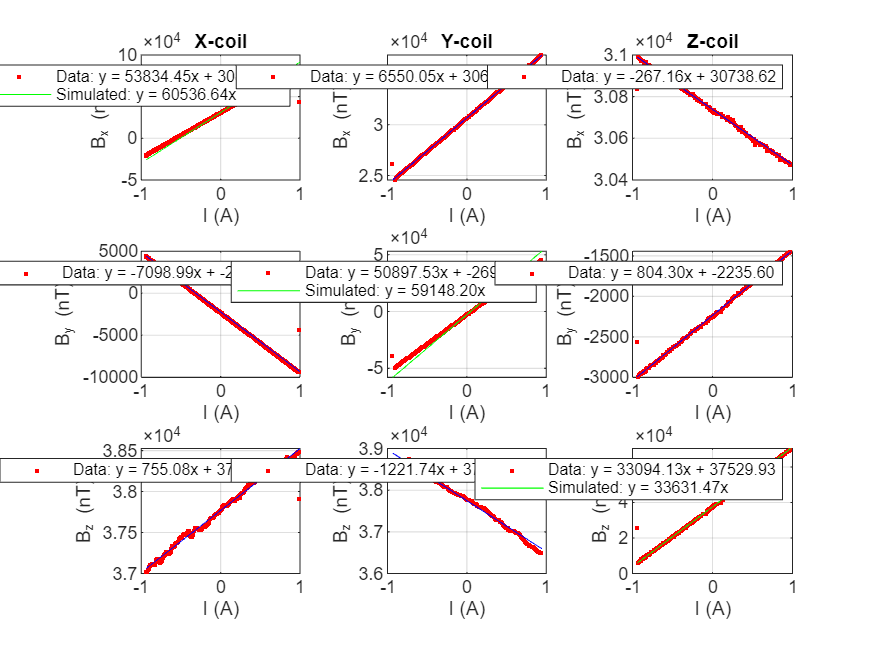

%%%Perform linear regression of degree 1 (a straight line)
degree_of_polynomial = 1;
%%%Linear regresion1
coeffs_x1 = polyfit(measuredData.xcoil.I, measuredData.xcoil.Bx , degree_of_polynomial);
coeffs_x2 = polyfit(measuredData.xcoil.I, measuredData.xcoil.By , degree_of_polynomial);
coeffs_x3 = polyfit(measuredData.xcoil.I, measuredData.xcoil.Bz , degree_of_polynomial);
%%%Linear regresion2
coeffs_y1 = polyfit(measuredData.ycoil.I, measuredData.ycoil.Bx , degree_of_polynomial);
coeffs_y2 = polyfit(measuredData.ycoil.I, measuredData.ycoil.By , degree_of_polynomial);
coeffs_y3 = polyfit(measuredData.ycoil.I, measuredData.ycoil.Bz , degree_of_polynomial);
%%%Linear regresion2
coeffs_z1 = polyfit(measuredData.zcoil.I, measuredData.zcoil.Bx , degree_of_polynomial);
coeffs_z2 = polyfit(measuredData.zcoil.I, measuredData.zcoil.By , degree_of_polynomial);
coeffs_z3 = polyfit(measuredData.zcoil.I, measuredData.zcoil.Bz , degree_of_polynomial);

%%%Create curves
%%create curves with the measured values
xcoil_fit_x = polyval(coeffs_x1, measuredData.xcoil.I); 
xcoil_regresion_x = sprintf('y = %.2fx + %.2f',coeffs_x1(1), coeffs_x1(2));
%%create curves with the measured values
xcoil_fit_y = polyval(coeffs_x2, measuredData.xcoil.I); 
xcoil_regresion_y = sprintf('y = %.2fx + %.2f',coeffs_x2(1), coeffs_x2(2));
%%create curves with the measured values
xcoil_fit_z = polyval(coeffs_x3, measuredData.xcoil.I); 
xcoil_regresion_z = sprintf('y = %.2fx + %.2f',coeffs_x3(1), coeffs_x3(2));

%%%Create curves
%%create curves with the measured values
ycoil_fit_x = polyval(coeffs_y1, measuredData.ycoil.I); 
ycoil_regresion_x = sprintf('y = %.2fx + %.2f',coeffs_y1(1), coeffs_y1(2));
%%create curves with the measured values
ycoil_fit_y = polyval(coeffs_y2, measuredData.ycoil.I); 
ycoil_regresion_y = sprintf('y = %.2fx + %.2f',coeffs_y2(1), coeffs_y2(2));
%%create curves with the measured values
ycoil_fit_z = polyval(coeffs_y3, measuredData.ycoil.I); 
ycoil_regresion_z = sprintf('y = %.2fx + %.2f',coeffs_y3(1), coeffs_y3(2));

%%%Create curves
%%create curves with the measured values
zcoil_fit_x = polyval(coeffs_z1, measuredData.zcoil.I); 
zcoil_regresion_x = sprintf('y = %.2fx + %.2f',coeffs_z1(1), coeffs_z1(2));
%%create curves with the measured values
zcoil_fit_y = polyval(coeffs_z2, measuredData.zcoil.I); 
zcoil_regresion_y = sprintf('y = %.2fx + %.2f',coeffs_z2(1), coeffs_z2(2));
%%create curves with the measured values
zcoil_fit_z = polyval(coeffs_z3, measuredData.zcoil.I); 
zcoil_regresion_z = sprintf('y = %.2fx + %.2f',coeffs_z3(1), coeffs_z3(2));

%%%Simulated data 
%%%Biot Savart law at x=0
mu_0 = 4*pi*1e-7;    % Permeability in the vacum
functBxyz0 = @(N,I,a,h) (4 * mu_0 * N *I * a^2) / (pi) * (1/((a^2 + (h/2)^2) * (2 * a^2 + (h/2)^2)^(1/2)));
coeff_teor = @(N,a,h) (4 * mu_0 * N * a^2) / (pi) * (1/((a^2 + (h/2)^2) * (2 * a^2 + (h/2)^2)^(1/2)));
calcN = @(a,h) (4 * mu_0 * a^2) / (pi) * (1/((a^2 + (h/2)^2) * (2 * a^2 + (h/2)^2)^(1/2)));

expN.x = (abs(coeffs_x1(1))+abs(coeffs_x2(1))+abs(coeffs_x3(1)))/(calcN(IS501NMTB.X.a,IS501NMTB.X.h)*1E9);
expN.y = (abs(coeffs_y1(1))+abs(coeffs_y2(1))+abs(coeffs_y3(1)))/(calcN(IS501NMTB.Y.a,IS501NMTB.Y.h)*1E9);
expN.z = (abs(coeffs_z1(1))+abs(coeffs_z2(1))+abs(coeffs_z3(1)))/(calcN(IS501NMTB.Z.a,IS501NMTB.Z.h)*1E9);

simulated.coeff.B_x = coeff_teor(IS501NMTB.X.N,IS501NMTB.X.a, IS501NMTB.X.h)*1E9;
simulated.coeff.B_y = coeff_teor(IS501NMTB.Y.N,IS501NMTB.Y.a, IS501NMTB.Y.h)*1E9;
simulated.coeff.B_z = coeff_teor(IS501NMTB.Z.N,IS501NMTB.Z.a, IS501NMTB.Z.h)*1E9;
xcoil_teo_regresion_x = sprintf('y = %.2fx',simulated.coeff.B_x);
ycoil_teo_regresion_y = sprintf('y = %.2fx',simulated.coeff.B_y);
zcoil_teo_regresion_z = sprintf('y = %.2fx',simulated.coeff.B_z);

simulated.B_x = functBxyz0(IS501NMTB.X.N, measuredData.xcoil.I, IS501NMTB.X.a, IS501NMTB.X.h)*1E9; %% In (nT)
simulated.B_y = functBxyz0(IS501NMTB.Y.N, measuredData.ycoil.I, IS501NMTB.Y.a, IS501NMTB.Y.h)*1E9; %% In (nT)
simulated.B_z = functBxyz0(IS501NMTB.Z.N, measuredData.zcoil.I, IS501NMTB.Z.a, IS501NMTB.Z.h)*1E9; %% In (nT)

errorx = (abs(coeffs_x1(1)-simulated.coeff.B_x)/coeffs_x1(1))*100;
errory = (abs(coeffs_y2(1)-simulated.coeff.B_y)/coeffs_y2(1))*100;
errorz = (abs(coeffs_z3(1)-simulated.coeff.B_z)/coeffs_z3(1))*100;

%%%Plot results
figure()
    subplot(3,3,1)
        plot(measuredData.xcoil.I,measuredData.xcoil.Bx,'r.'); hold on; grid on;
        %plot(measuredData.xcoil.I, xcoil_fit_x, 'b-');
        plot(measuredData.xcoil.I, simulated.B_x+coeffs_x1(2),'g'),
        title('X-coil'); legend(['Data: ', xcoil_regresion_x], ['Simulated: ',xcoil_teo_regresion_x]);
        xlabel('I (A)'); ylabel('B_x (nT)');
    subplot(3,3,2)
        h1 = plot(measuredData.ycoil.I,measuredData.ycoil.Bx,'r.'); hold on; grid on;
        plot(measuredData.ycoil.I, ycoil_fit_x, 'b-');
        title('Y-coil'); legend(h1,['Data: ', ycoil_regresion_x]);
        xlabel('I (A)'); ylabel('B_x (nT)');
    subplot(3,3,3)
        h1 = plot(measuredData.zcoil.I,measuredData.zcoil.Bx,'r.'); hold on; grid on;
        plot(measuredData.zcoil.I, zcoil_fit_x, 'b-');
        title('Z-coil'); legend(h1,['Data: ', zcoil_regresion_x]);
        xlabel('I (A)'); ylabel('B_x (nT)');
        
    subplot(3,3,4)
        h1 = plot(measuredData.xcoil.I,measuredData.xcoil.By,'r.'); hold on; grid on;
        plot(measuredData.xcoil.I, xcoil_fit_y, 'b-');
        xlabel('I (A)'); ylabel('B_y (nT)'); legend(h1,['Data: ', xcoil_regresion_y]);
    subplot(3,3,5)
        plot(measuredData.ycoil.I,measuredData.ycoil.By,'r.'); hold on; grid on;
        %plot(measuredData.ycoil.I, ycoil_fit_y, 'b-');
        plot(measuredData.ycoil.I, simulated.B_y+coeffs_y2(2),'g'),
        xlabel('I (A)'); ylabel('B_y (nT)'); 
        legend(['Data: ', ycoil_regresion_y],['Simulated: ',ycoil_teo_regresion_y]);
    subplot(3,3,6)
        h1 = plot(measuredData.zcoil.I,measuredData.zcoil.By,'r.'); hold on; grid on;
        plot(measuredData.zcoil.I, zcoil_fit_y, 'b-');
        xlabel('I (A)'); ylabel('B_y (nT)'); legend(h1,['Data: ', zcoil_regresion_y]);

    subplot(3,3,7)
        h2 = plot(measuredData.xcoil.I,measuredData.xcoil.Bz,'r.'); hold on; grid on;
        plot(measuredData.xcoil.I, xcoil_fit_z, 'b-');
        xlabel('I (A)'); ylabel('B_z (nT)'); legend(h2,['Data: ', xcoil_regresion_z]);
    subplot(3,3,8)
        h1 = plot(measuredData.ycoil.I,measuredData.ycoil.Bz,'r.'); hold on; grid on;
        plot(measuredData.ycoil.I, ycoil_fit_z, 'b-');
        xlabel('I (A)'); ylabel('B_z (nT)'); legend(h1,['Data: ', ycoil_regresion_z]);
    subplot(3,3,9)
        plot(measuredData.zcoil.I,measuredData.zcoil.Bz,'r.'); hold on; grid on;
        %plot(measuredData.zcoil.I, zcoil_fit_z, 'b-');
        plot(measuredData.zcoil.I, simulated.B_z+coeffs_z3(2),'g'),
        xlabel('I (A)'); ylabel('B_z (nT)'); 
        legend(['Data: ', zcoil_regresion_z],['Simulated: ',zcoil_teo_regresion_z]);

Compare data from 2021 and 2024

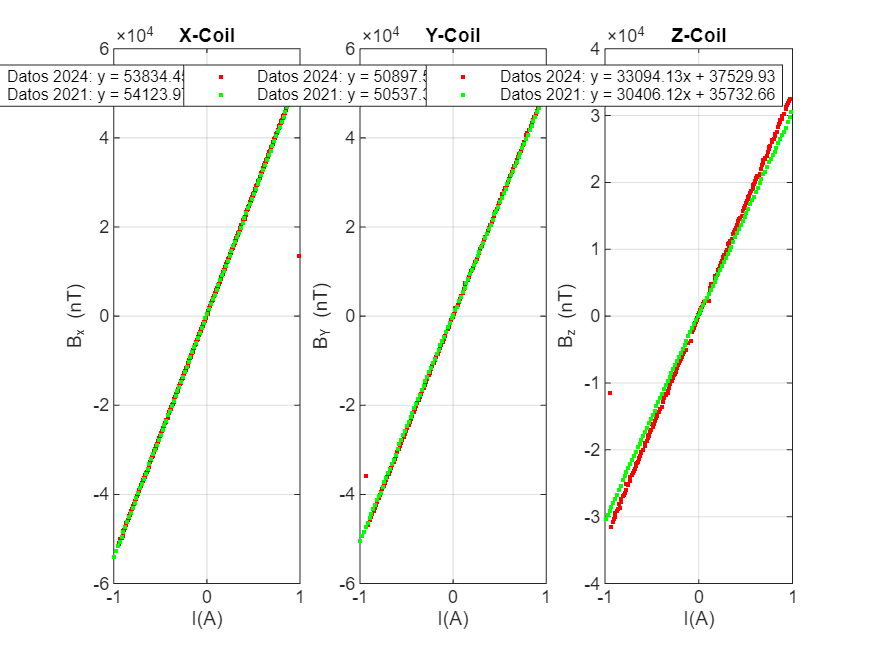

%%%Plot the data and the linear regression line
figure()
subplot(1,3,1)
    plot(measuredData.xcoil.I,measuredData.xcoil.Bx-coeffs_x1(2),'r.'); hold on; grid on;
    plot(jhonny.xcoil.I,jhonny.xcoil.B-jhonny.coeffsB.x(2),'g.');
    xlabel('I(A)'); ylabel('B_x (nT)'); grid on; title('X-Coil');
    legend(['Datos 2024: ', xcoil_regresion_x],['Datos 2021: ', jhonny.ecuacion_regresionB.x])
subplot(1,3,2)
    plot(measuredData.ycoil.I,measuredData.ycoil.By-coeffs_y2(2),'r.'); hold on; grid on;
    plot(jhonny.ycoil.I,jhonny.ycoil.B-jhonny.coeffsB.y(2),'g.');
    xlabel('I(A)'); ylabel('B_Y (nT)'); grid on; title('Y-Coil');
    legend(['Datos 2024: ', ycoil_regresion_y],['Datos 2021: ', jhonny.ecuacion_regresionB.y])
subplot(1,3,3)
    plot(measuredData.zcoil.I,measuredData.zcoil.Bz-coeffs_z3(2),'r.'); hold on; grid on;
    plot(jhonny.zcoil.I,jhonny.zcoil.B-jhonny.coeffsB.z(2),'g.');
    xlabel('I(A)'); ylabel('B_z (nT)'); grid on; title('Z-Coil');
    legend(['Datos 2024: ', zcoil_regresion_z],['Datos 2021: ', jhonny.ecuacion_regresionB.z]);

**System identification**


% subplot(1,3,2)
% plot(y_coil_data(2,:), y_coil_data(1,:),'r.','LineWidth',3);hold on;
% ylabel('Voltage(V)'); xlabel('Current(A)'); grid on; title('Y-Coil Measures')
% 
% subplot(1,3,3)
% plot(z_coil_data(2,:), z_coil_data(1,:),'r.','LineWidth',3);hold on;
% ylabel('Voltage(V)'); xlabel('Current(A)'); grid on; title('Z-Coil Measures')

% x_fit = linspace(min(x_coil_data(2,:)), max(x_coil_data(2,:)), 50); % x values for the regression line
% y_fit = polyval(coeffs, x_fit); % Calculate fitted y values
% plot(x_fit, y_fit, 'b--','LineWidth',2); % Linear regression line
% legend('Data', 'Linear Regression');
% grid on; hold off; % Release the plot

## 1. Magnetometer Data Reading

In this chapter, we will emphasize the IS501 previous steps required to start utilizing it. To achieve this, it is necessary to establish a connection with the magnetometers. Magnetometer communication is achieved through serial data communication.

The driver that we need to install is called "USB-SERIAL CH340." You can install the driver from the following link: 

[CH340 Drivers for Windows, Mac and Linux (gogo.co.nz)](https://sparks.gogo.co.nz/ch340.html).

Subsequently, it is imperative to establish the serial communication.

%disp("Display available Serial Ports:");
%availableSerialPorts = IDSerialComs("available");
%disp(availableSerialPorts);

Then we checked the name USB-SERIAL CH430 and a serial object is necesary to be created.

% for i = 1:size(availableSerialPorts,1)
%     if strcmp('USB-SERIAL CH340',availableSerialPorts{i,1})
%         try
%             s = serialport(availableSerialPorts{i,2},9600);
%             disp('Port connected sucessfully.');
%         catch Err
%             disp(Err.message);
%         end
%     end
% end

Once the magnetometers are connected then start to display and stream data. The data has te following format:

- Mag_xAMag_xBMag_xC

Where 

- Mag_x: Magnetic field in X axis in (nT) whit sign;

- Mag_y: Magnetic field in Y axis in (nT) whit sign;

- Mag_z: Magnetic field in Z axis in (nT) whit sign;

The data was measured with the following code:

%data = read(s,27,"string")

Then the data was split using the sscan function:

%B = sscanf(data,'%fA%fB%fC');
%fprintf('Magnetic Field in X: %.2f nT, in Y: %.2f nT, in Z: %.2f nT',B(1),B(2),B(3))

Close serial port

%delete(s)

## 2. Magnetometer Calibration

### 2.1. Background

A magnetometer is a device capable of detect the magnetic field strength along the X, Y and Z axes. In the **IS501 NMTB **the magnetometer is an important device due to it is used a feedback for the simulation of the earth magnetic field.

Ideally, a three-axis magnetometer measures in the absent of any magnetic interference, magnetometer readings measure the earth's magnetic field [8]. If magnetometer measurements are made in all directions, the measurements should lie on a sphere with a radius of the magnetic field strength [8].

### 2.2. Hard Iron Calibration 

According to [8], noise sources and manufacturing defects degrade a magnetometer's measurement. The most striking of these are hard iron effects. Hard iron effects are stationary interfering magnetic noise sources. Often, these come from other metallic objects on the circuit board with the magnetometer. The hard iron effects shift the origin of the ideal sphere.

### 2.3. Soft Iron Calibration

According to [8], Soft iron effects are more subtle. They arise from objects near the sensor which distort the surrounding magnetic field. These have the effect of stretching and tilting the sphere of ideal measurements. The resulting measurements lie on an ellipsoid.

### 2.4 Correction Technique

In [7] it is mentioned a general process to perform a compass calibration. The process carry out a soft and hard iron compensation wich considers all the magnetic distortions. In [7] it is recomended that the calibration of the compasses must be carried out in its fully operational configuration; all sensors (sensor, electronics and power sources) must be powered on. This will ensure that any current carrying conductors in the vicinity of the sensor (producing hard iron distortion) will also be compensated. Subsequently, users would then have to rotate the entire system (magnetometer) in an environment with a uniform Earth magnetic field. 

In [8] it is explained the $magcal$ matlab function that is used to determine the magnetometer calibration. In [8] the uncalibrated magnetometer data can be modeled as an ellipsoid with equation.


$$(x-b)R(x-b)^T=\beta^2$$


Where: 

$R$ is a 3x3 matrix, $b$ is a 1x3 vector defining the ellipsoid center, $x$ is a 1-3 vector with the uncalibrated magnetometer measurements, and $\beta$ is a scalar indicating the magnetic field strength. 

The $magcal$ function produces correction coefficients that take measurements witch lie on an offset ellipsoid and transform them lo lie on an ideal sphere centered at the origin. The correction data cabe done with equation.


$$m = (x - b) A$$


Here $x$ is a 1-3 array of uncalibrated magnetometer measurements and $m$ is the 1-3 array of corrected magnetometer measurements, which lie on a sphere. The matrix $A$ has a determinant of 1 and is the matrix square root of *R*. Additionally, *A* has the same form as *R* : the identity, a diagonal, or a symmetric matrix. Because these kinds of matrices cannot impart a rotation, the matrix *A* will not rotate the magnetometer data during correction.

### 2.5. Residual Error

The residual error defined by [8] is a quality indicator which is the sum of the distances between the calibrated data and a sphere of radius $\beta$.


$$E=\frac{1}{2\beta^2}\sqrt{\frac{\sum||(x-b)A||^2-\beta^2}{N}}$$


### 2.3. Data Set

The magnetometer calibration was measured and stored in order to perform a previous hard and soft iron calibration. 

#### 2.3.1. Record magnetic data

The data recorded was measured in the **IS501 NMTB **in the center of the magnetic chamber. The data was measured with the following program. 

### 1.2. Magnetometer calibration

Read the obtained data.

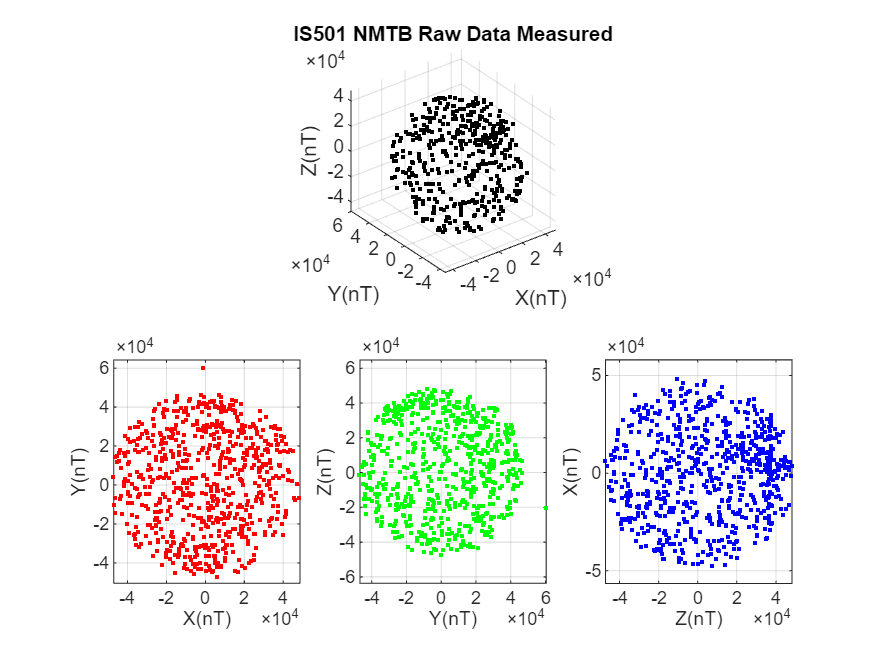

%%% Read data measured
fileName1 = 'rawMagData_Epoch_2023_05_09.mat';
load(fileName1);
rawDataStore1 = rawDataStore;

fileName2 = 'rawMagData_Epoch_2023_07_09.mat';
load(fileName2);
rawDataStore2 = rawDataStore;

%%% Combine data measured two days
rawDataStore = horzcat(rawDataStore1,rawDataStore2);

%%%Load the choosen to environment
figure()
subplot(2,3,1:3)
    plot3(rawDataStore1(1,:),rawDataStore1(2,:),rawDataStore1(3,:),'k.','LineWidth',5); hold on;
    xlabel('X(nT)'); ylabel('Y(nT)'); zlabel('Z(nT)');
    axis equal; grid on; title('IS501 NMTB Raw Data Measured');
subplot(2,3,4)
    h1 = plot(rawDataStore(1,:), rawDataStore(2,:),'r.','LineWidth',5); hold on;
    xlabel('X(nT)'); ylabel('Y(nT)'); axis equal; grid on;
subplot(2,3,5)
    h2 = plot(rawDataStore(2,:), rawDataStore(3,:),'g.','LineWidth',5); hold on;
    xlabel('Y(nT)'); ylabel('Z(nT)'); axis equal; grid on;    
subplot(2,3,6)
    h3 = plot(rawDataStore(3,:), rawDataStore(1,:),'b.','LineWidth',5); hold on;
    xlabel('Z(nT)'); ylabel('X(nT)'); axis equal; grid on;  

% % % %%% magnetometer data, simply call the function as: 
% % % [A,b,expMFS]  = magcal(rawDataStore','auto');
% % % xCorrected = (rawDataStore'-b)*A;
% % % 
% % % 
% % % %%% Plot the original and corrected data. Show the ellipsoid that best fits
% % % %%% the original data. Show the sphere on which the corrected data should
% % % %%% lie.
% % % de = HelperDrawEllipsoid;
% % % de.plotCalibrated(A,b,expMFS,rawDataStore',xCorrected,'auto');
% % % % The |magcal| function uses a variety of solvers to minimize the residual
% % % % error. The residual error is the sum of the distances between the
% % % % calibrated data and a sphere of radius |expMFS|.
% % % %
% % % % $$E = \frac{1}{2 \beta^2}\sqrt{ \frac{\sum  ||(x-b)A||^2 - \beta^2}{N} }$$
% % % %
% % % N = size(xCorrected,2);
% % % r = sum(xCorrected.^2,2) - expMFS.^2;
% % % E = sqrt(r.'*r./N)./(2*expMFS.^2);
% % % fprintf('Residual error in corrected data : %.2f\n\n',E);

The calculated parameters made for calibration are:

% % % disp(A)
% % % disp(b)

## 2. Power Source Control

The IS506 has three Power Sources (IT6433, IT6431, IT6433). The programing catalog can be seen in.

[IT6411-33-Programming-Guide.pdf (altoo.dk)](https://www.altoo.dk/files/itech/manuals/IT6411-33-Programming-Guide.pdf).

The three Power sources has the following network configuration.

- X-Axis: IT6433, IP: 192.168.0.10, Mask: 255.255.255.0, Gateway:192.168.0.1

- Y-Axis: IT6433, IP: 192.168.0.11, Mask: 255.255.255.0, Gateway:192.168.0.1

- Z-Axis: IT6433, IP: 192.168.0.12, Mask: 255.255.255.0, Gateway:192.168.0.1

The three power sources are connecter with the controller PC through a 5 output swith model: TL-SF1005M. The control computer has the following network configuration:

- Control computer: IP: 192.168.0.20, Mask: 255.255.255.0, Gateway: 192.168.0.1

The three DC founts only work with the socket port 30000 and to send the SCPI comads.

% % % % Create TCP/IP object 't'. Specify server machine and port number. 
% % % x_axis = tcpip('192.168.0.10', 30000); %%
% % % 
% % % % Set size of receiving buffer, if needed. 
% % % set(x_axis, 'InputBufferSize', 30000); 
% % % 
% % % % Open connection to the server. 
% % % fopen(x_axis); 
% % % 
% % % % Transmit data to the server (SCPI mode). 
% % % fprintf(x_axis, '*IDN?'); 
% % % 
% % % % Pause for the communication delay, if needed. 
% % % pause(1) 
% % % 
% % % % Receive lines of data from server 
% % % while (get(x_axis, 'BytesAvailable') > 0) 
% % % x_axis.BytesAvailable 
% % % DataReceived = fscanf(x_axis) 
% % % end 
% % % 
% % % % Disconnect and clean up the server connection. 
% % % fclose(x_axis); 
% % % delete(x_axis); 
% % % clear x_axis 

To controll the Power DC it is necessary to enter into the remote control mode. This is done with the SCPI command:

The commands to set general parameters like Current and Voltage are SET with the following commands. The CURRent 1.0 value sets the maximun current value, the VOLTage value set the voltage value and the OUTPut ON command turn ON the voltage value.

The Following commands read the voltage, current and power delivered by the power source and measured by the voltimeter and amperimeter inside the power source.

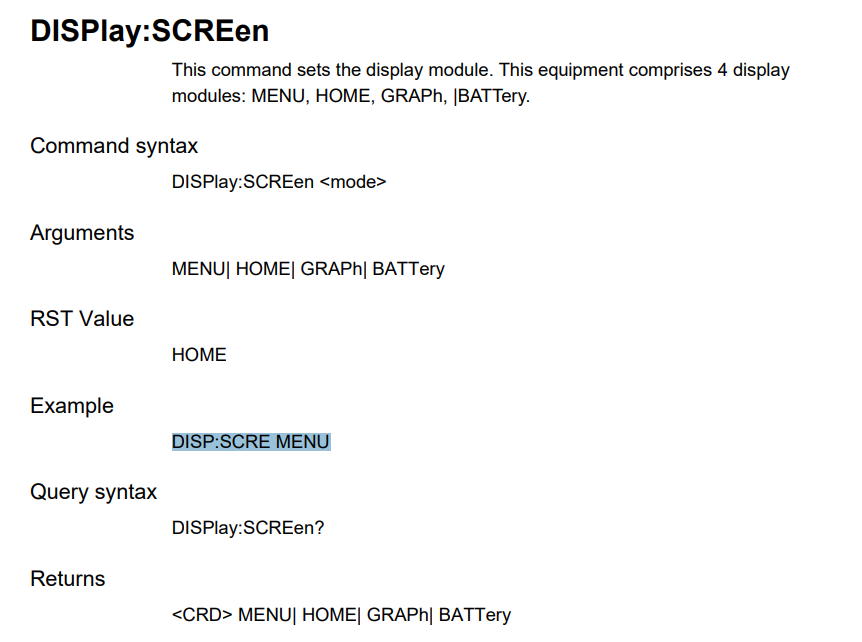

% % % % Create TCP/IP object 't'. Specify server machine and port number. 
% % % x_axis = tcpip('192.168.0.10', 30000); %%
% % % 
% % % % Set size of receiving buffer, if needed. 
% % % set(x_axis, 'InputBufferSize', 30000); 
% % % 
% % % % Open connection to the server. 
% % % fopen(x_axis); 
% % % 
% % % % Pause for the communication delay, if needed. 
% % % pause(1) 
% % % 
% % % % Transmit data to the server (SCPI mode). 
% % % fprintf(x_axis, 'SYSTem:REMote');
% % % fprintf(x_axis,'DISP:SCRE HOME');
% % % fprintf(x_axis, 'CURRent 1.0');
% % % %fprintf(x_axis, 'VOLTage 12');
% % % fprintf(x_axis, 'OUTPut ON');
% % % fprintf(x_axis, 'MEASure:VOLTage?');
% % % 
% % % % Receive lines of data from server 
% % % while (get(x_axis, 'BytesAvailable') > 0) 
% % % x_axis.BytesAvailable 
% % % DataReceived = fscanf(x_axis) 
% % % end 
% % % 
% % % % Disconnect and clean up the server connection. 
% % % fclose(x_axis); 
% % % delete(x_axis); 
% % % clear x_axis 

% % % % Transmit data to the server (SCPI mode). 
% % % fprintf(x_axis, 'SYSTem:LOCal'); 

## Magnetic Coils model

We send different voltages throught the sources in order to dermine the resistance and perform an accurate control.

Preliminarly we measure the resistenance in each coil with the multimeter VICTOR VC980 obtained the following values:

- X-axis: 15.16-15.20 $\Omega$  operating range (-15DCV/ +15DCV).

- Y-axis: 7.80-7.87 $\Omega$ operating range (-7DCV/ +7DCV).

- Z-axis: 13.83-13.88 $\Omega$ operating range (-10DCV/ +10DCV).

For security reasons, the maximun current that we will use in this experiment it is confined from -1A to 1A for each Coil. 

First, we will start the comunication with each coil

% % % %%Data to store the obtained values
% % % x_coil_data = [];
% % % y_coil_data = [];
% % % z_coil_data = [];
% % % 
% % % % Create TCP/IP object 't'. Specify server machine and port number. 
% % % x_axis = tcpip('192.168.0.10', 30000); 
% % % y_axis = tcpip('192.168.0.11', 30000); 
% % % z_axis = tcpip('192.168.0.12', 30000); 
% % % 
% % % % Set size of receiving buffer, if needed. 
% % % set(x_axis, 'InputBufferSize', 30000); 
% % % set(y_axis, 'InputBufferSize', 30000); 
% % % set(z_axis, 'InputBufferSize', 30000); 

### For X axis

% % % % Open connection to the server. 
% % % fopen(x_axis); pause(1);
% % % 
% % % % Send preliminary data
% % % fprintf(x_axis, 'SYSTem:REMote;DISP:SCRE HOME;CURRent 1.0');
% % % 
% % % figure()
% % % for i = -15:0.1:15
% % %     fprintf(x_axis,['VOLTage ', num2str(i,'%.2f')]);
% % %     %disp(['VOLTage ', num2str(i,'%.2f')]);
% % %     fprintf(x_axis, 'OUTPut ON');
% % %     %%% Require the measured voltage and current
% % %     fprintf(x_axis, 'MEASure:VOLTage?;MEASure:CURRent?');
% % %     pause(0.5);
% % %     %%% Receive lines of data from server 
% % %     while (get(x_axis, 'BytesAvailable') > 0) 
% % %         x_axis.BytesAvailable;
% % %         DataReceived = fscanf(x_axis);
% % %     end  
% % % 
% % %     if exist('DataReceived','var')
% % %         if (length(DataReceived)>13)
% % %         numDat = sscanf(DataReceived,'%f%f');
% % %         x_coil_data = [x_coil_data, numDat];
% % %         plot(numDat(2), numDat(1),'r.','LineWidth',3');hold on
% % %         xlabel('A'); ylabel('V'); grid on; title('X-Coil Measures')
% % %         end
% % %     end
% % %     pause(2);
% % % end
% % % % Disconnect and clean up the server connection. 
% % % fclose(x_axis); 
% % % delete(x_axis); 
% % % clear x_axis 

% % % xCoilDataFileName = 'xCoil_Epoch_2023_07_09.mat';
% % % save(xCoilDataFileName,'x_coil_data');

In order to characterize the power sources and the resistance of the power sources, we will find the coils resistance. 

% % % %%% Read data measured
% % % fileName = 'xCoil_Epoch_2023_07_09.mat';
% % % load(fileName);
% % % 
% % % % Perform linear regression of degree 1 (a straight line)
% % % degree_of_polynomial = 1;
% % % coeffs = polyfit(x_coil_data(2,:), x_coil_data(1,:), degree_of_polynomial);
% % % 
% % % % Coeffs will contain the coefficients of the fitted polynomial (in this case, the slope and intercept)
% % % slope = coeffs(1);
% % % intercept = coeffs(2);
% % % 
% % % % Plot the data and the linear regression line
% % % figure()
% % % plot(x_coil_data(2,:),x_coil_data(1,:),'r.','LineWidth',3);hold on; % Keep the current plot
% % % ylabel('Voltage(V)'); xlabel('Current(A)'); grid on; title('X-Coil Measures')
% % % 
% % % x_fit = linspace(min(x_coil_data(2,:)), max(x_coil_data(2,:)), 50); % x values for the regression line
% % % y_fit = polyval(coeffs, x_fit); % Calculate fitted y values
% % % plot(x_fit, y_fit, 'b--','LineWidth',2); % Linear regression line
% % % legend('Data', 'Linear Regression');
% % % grid on; hold off; % Release the plot
% % % % Display the slope and intercept
% % % fprintf('Slope: %.2f, Intercept: %.2f\n', slope, intercept);

The linear regression is described in the following equation.


$$V = slope * I + Intercept$$


And it can be compared with Ohm law wich is described in the following form.


$$V = IR$$


Where $V$ is voltage, $I$ is current and $R$ is the resistor. Due to the intercept is so near to zero, then we can conclude that the slope value is the same that the resistance value. Then: 

% % % % Display the slope and intercept
% % % fprintf('Resistance of the X coil: %.2f omega\n', slope);

For y axis.

% % % % Open connection to the server. 
% % % 
% % % fopen(y_axis); pause(1);
% % % 
% % % % Send preliminary data
% % % fprintf(y_axis, 'SYSTem:REMote;DISP:SCRE HOME;CURRent 1.0');
% % % 
% % % figure()
% % % for i = -7:0.1:7
% % %     fprintf(y_axis,['VOLTage ', num2str(i,'%.2f')]);
% % %     %disp(['VOLTage ', num2str(i,'%.2f')]);
% % %     fprintf(y_axis, 'OUTPut ON');
% % %     %%% Require the measured voltage and current
% % %     fprintf(y_axis, 'MEASure:VOLTage?;MEASure:CURRent?');
% % %     pause(0.5);
% % %     %%% Receive lines of data from server 
% % %     while (get(y_axis, 'BytesAvailable') > 0) 
% % %         y_axis.BytesAvailable;
% % %         DataReceived = fscanf(y_axis);
% % %     end  
% % % 
% % %     if exist('DataReceived','var')
% % %         if (length(DataReceived)>13)
% % %         numDat = sscanf(DataReceived,'%f%f');
% % %         y_coil_data = [y_coil_data, numDat];
% % %         plot(numDat(2), numDat(1),'b.','LineWidth',3');hold on
% % %         xlabel('A'); ylabel('V'); grid on; title('Y-Coil Measures')
% % %         end
% % %     end
% % %     pause(2);
% % % end

% % % yCoilDataFileName = 'yCoil_Epoch_2023_07_09.mat';
% % % save(yCoilDataFileName,'y_coil_data');

In order to characterize the power sources and the resistance of the power sources, we will find the coils resistance. 

% % % %%% Read data measured
% % % fileName = 'yCoil_Epoch_2023_07_09.mat';
% % % load(fileName);
% % % 
% % % % Perform linear regression of degree 1 (a straight line)
% % % degree_of_polynomial = 1;
% % % coeffs = polyfit(y_coil_data(2,:), y_coil_data(1,:), degree_of_polynomial);
% % % 
% % % % Coeffs will contain the coefficients of the fitted polynomial (in this case, the slope and intercept)
% % % slope = coeffs(1);
% % % intercept = coeffs(2);
% % % 
% % % % Plot the data and the linear regression line
% % % figure()
% % % plot(y_coil_data(2,2:end),y_coil_data(1,2:end),'b.','LineWidth',3);hold on; % Keep the current plot
% % % ylabel('Voltage(V)'); xlabel('Current(A)'); grid on; title('Y-Coil Measures')
% % % 
% % % x_fit = linspace(min(y_coil_data(2,2:end)), max(y_coil_data(2,2:end)), 50); % x values for the regression line
% % % y_fit = polyval(coeffs, x_fit); % Calculate fitted y values
% % % plot(x_fit, y_fit, 'r--','LineWidth',2); % Linear regression line
% % % legend('Data', 'Linear Regression');
% % % grid on; hold off; % Release the plot
% % % % Display the slope and intercept
% % % fprintf('Slope: %.2f, Intercept: %.2f\n', slope, intercept);

The linear regression is described in the following equation.


$$V = slope * I + Intercept$$


And it can be compared with Ohm law wich is described in the following form.


$$V = IR$$


Where $V$ is voltage, $I$ is current and $R$ is the resistor. Due to the intercept is so near to zero, then we can conclude that the slope value is the same that the resistance value. Then: 

% % % % Display the slope and intercept
% % % fprintf('Resistance of the Y coil: %.2f omega\n', slope);

For the Z

% % % % Open connection to the server. 
% % % fopen(z_axis); pause(1);
% % % 
% % % % Send preliminary data
% % % fprintf(z_axis, 'SYSTem:REMote;DISP:SCRE HOME;CURRent 1.0');
% % % 
% % % figure()
% % % for i = -10:0.1:10
% % %     fprintf(z_axis,['VOLTage ', num2str(i,'%.2f')]);
% % %     %disp(['VOLTage ', num2str(i,'%.2f')]);
% % %     fprintf(z_axis, 'OUTPut ON');
% % %     %%% Require the measured voltage and current
% % %     fprintf(z_axis, 'MEASure:VOLTage?;MEASure:CURRent?');
% % %     pause(0.5);
% % %     %%% Receive lines of data from server 
% % %     while (get(z_axis, 'BytesAvailable') > 0) 
% % %         z_axis.BytesAvailable;
% % %         DataReceived = fscanf(z_axis);
% % %     end  
% % % 
% % %     if exist('DataReceived','var')
% % %         if (length(DataReceived)>13)
% % %         numDat = sscanf(DataReceived,'%f%f');
% % %         z_coil_data = [z_coil_data, numDat];
% % %         plot(numDat(2), numDat(1),'b.','LineWidth',3');hold on
% % %         xlabel('A'); ylabel('V'); grid on; title('Z-Coil Measures')
% % %         end
% % %     end
% % %     pause(2);
% % % end

% % % yCoilDataFileName = 'zCoil_Epoch_2023_07_09.mat';
% % % save(yCoilDataFileName,'z_coil_data');

In order to characterize the power sources and the resistance of the power sources, we will find the coils resistance. 

% % % %%% Read data measured
% % % fileName = 'zCoil_Epoch_2023_07_09.mat';
% % % load(fileName);
% % % 
% % % % Perform linear regression of degree 1 (a straight line)
% % % degree_of_polynomial = 1;
% % % coeffs = polyfit(z_coil_data(2,:), z_coil_data(1,:), degree_of_polynomial);
% % % 
% % % % Coeffs will contain the coefficients of the fitted polynomial (in this case, the slope and intercept)
% % % slope = coeffs(1);
% % % intercept = coeffs(2);
% % % 
% % % % Plot the data and the linear regression line
% % % figure()
% % % plot(z_coil_data(2,2:end),z_coil_data(1,2:end),'r.','LineWidth',3);hold on; % Keep the current plot
% % % ylabel('Voltage(V)'); xlabel('Current(A)'); grid on; title('Z-Coil Measures')
% % % 
% % % x_fit = linspace(min(z_coil_data(2,2:end)), max(z_coil_data(2,2:end)), 50); % x values for the regression line
% % % y_fit = polyval(coeffs, x_fit); % Calculate fitted y values
% % % plot(x_fit, y_fit, 'b--','LineWidth',2); % Linear regression line
% % % legend('Data', 'Linear Regression');
% % % grid on; hold off; % Release the plot
% % % % Display the slope and intercept
% % % fprintf('Slope: %.2f, Intercept: %.2f\n', slope, intercept);

The linear regression is described in the following equation.


$$V = slope * I + Intercept$$


And it can be compared with Ohm law wich is described in the following form.


$$V = IR$$


Where $V$ is voltage, $I$ is current and $R$ is the resistor. Due to the intercept is so near to zero, then we can conclude that the slope value is the same that the resistance value. Then: 

% % % % Display the slope and intercept
% % % fprintf('Resistance of the Z coil: %.2f omega\n', slope);

## Get Real Mode

We will send step voltage in each coil and then we will measure the magnetic field to see the behavior.

### **X axis**

Start conection with the sensor.

% % % disp("Display available Serial Ports:");
% % % availableSerialPorts = IDSerialComs("available");
% % % disp(availableSerialPorts);

Then we checked the name USB-SERIAL CH430 and a serial object is necesary to be created.

% % % for i = 1:size(availableSerialPorts,1)
% % %     if strcmp('USB-SERIAL CH340',availableSerialPorts{i,1})
% % %         try
% % %             s = serialport(availableSerialPorts{i,2},9600);
% % %             disp('Port connected sucessfully.');
% % %         catch Err
% % %             disp(Err.message);
% % %         end
% % %     end
% % % end

Start conexion with the Power sources

% % % % Create TCP/IP object 't'. Specify server machine and port number. 
% % % x_axis = tcpip('192.168.0.10', 30000);
% % % % Set size of receiving buffer, if needed. 
% % % set(x_axis, 'InputBufferSize', 30000); 
% % % % Open connection to the server. 
% % % fopen(x_axis); pause(1);
% % % % Start Remote operation and set as maximum current 1A.
% % % fprintf(x_axis, 'SYSTem:REMote;DISP:SCRE HOME;CURRent 1.0');

Start measurements with voltage ramps.

% % % figure()
% % % x_coil_data_mag = [];
% % % ts =tic;
% % % for i = -15:0.1:15
% % %     t1 = toc(ts);
% % %     fprintf(x_axis,['VOLTage ', num2str(i,'%.2f')]);
% % %     %disp(['VOLTage ', num2str(i,'%.2f')]);
% % %     fprintf(x_axis, 'OUTPut ON');
% % %     %%% Require the measured voltage and current
% % %     fprintf(x_axis, 'MEASure:VOLTage?;MEASure:CURRent?');
% % %     pause(0.5);
% % %     %%% Receive lines of data from server 
% % %     while (get(x_axis, 'BytesAvailable') > 0) 
% % %         x_axis.BytesAvailable;
% % %         DataReceived = fscanf(x_axis);
% % %     end  
% % % 
% % %     if exist('DataReceived','var')
% % %         if (length(DataReceived)>13)
% % %         numDat = sscanf(DataReceived,'%f%f');
% % %         %x_coil_data = [x_coil_data, numDat];
% % %         rawData = read(s,27,"string");
% % %         actualMeasures = sscanf(rawData,'%fA%fB%fC');
% % %         x_coil_data_mag = [x_coil_data_mag, vertcat(t1,numDat,actualMeasures)];
% % %         subplot(2,1,1)
% % %             plot(numDat(2), numDat(1),'r.','LineWidth',3');hold on
% % %             xlabel('A'); ylabel('V'); grid on; title('X-Coil Measures')
% % %         subplot(2,1,2)
% % %             h1=plot(i, actualMeasures(1),'r.','LineWidth',3'); hold on;
% % %             h2=plot(i, actualMeasures(2),'b.','LineWidth',3'); 
% % %             h3=plot(i, actualMeasures(3),'g.','LineWidth',3'); grid on;
% % %             xlabel('V'); ylabel('nT'); title('Magnetic Field');
% % %             legend([h1,h2,h3],'X','Y','Z');
% % %         end
% % %     end
% % %     pause(3);
% % % end

Close all ports.

% % % fclose(x_axis); 
% % % delete(x_axis); 
% % % clear x_axis 
% % % delete(s)

% % % xCoilDataFileNameMag = 'zCoil_mag_Epoch_2023_14_09.mat';
% % % save(xCoilDataFileNameMag,'x_coil_data_mag');

For the Y axis

Start conexion with the Power sources

% % % % Create TCP/IP object 't'. Specify server machine and port number. 
% % % y_axis = tcpip('192.168.0.11', 30000);
% % % % Set size of receiving buffer, if needed. 
% % % set(y_axis, 'InputBufferSize', 30000); 
% % % % Open connection to the server. 
% % % fopen(y_axis); pause(1);
% % % % Start Remote operation and set as maximum current 1A.
% % % fprintf(y_axis, 'SYSTem:REMote;DISP:SCRE HOME;CURRent 1.0');

% % % figure()
% % % y_coil_data_mag = [];
% % % for i = -7:0.1:7
% % %     fprintf(y_axis,['VOLTage ', num2str(i,'%.2f')]);
% % %     %disp(['VOLTage ', num2str(i,'%.2f')]);
% % %     fprintf(y_axis, 'OUTPut ON');
% % %     %%% Require the measured voltage and current
% % %     fprintf(y_axis, 'MEASure:VOLTage?;MEASure:CURRent?');
% % %     pause(0.5);
% % %     %%% Receive lines of data from server 
% % %     while (get(y_axis, 'BytesAvailable') > 0) 
% % %         y_axis.BytesAvailable;
% % %         DataReceived = fscanf(y_axis);
% % %     end  
% % % 
% % %     if exist('DataReceived','var')
% % %         if (length(DataReceived)>13)
% % %         numDat = sscanf(DataReceived,'%f%f');
% % %         %x_coil_data = [x_coil_data, numDat];
% % %         rawData = read(s,27,"string");
% % %         actualMeasures = sscanf(rawData,'%fA%fB%fC');
% % %         y_coil_data_mag = [y_coil_data_mag, vertcat(numDat,actualMeasures)];
% % %         subplot(2,1,1)
% % %             plot(numDat(2), numDat(1),'r.','LineWidth',3');hold on
% % %             xlabel('A'); ylabel('V'); grid on; title('Y-Coil Measures')
% % %         subplot(2,1,2)
% % %             h1=plot(i, actualMeasures(1),'r.','LineWidth',3'); hold on;
% % %             h2=plot(i, actualMeasures(2),'b.','LineWidth',3'); 
% % %             h3=plot(i, actualMeasures(3),'g.','LineWidth',3'); grid on;
% % %             xlabel('V'); ylabel('nT'); title('Magnetic Field');
% % %             legend([h1,h2,h3],'X','Y','Z');
% % %         end
% % %     end
% % %     pause(3);
% % % end

% % % yCoilDataFileNameMag = 'yCoil_mag_Epoch_2023_14_09.mat';
% % % save(yCoilDataFileNameMag,'y_coil_data_mag');

For the Z axis

Start conexion with the Power sources

% % % % Create TCP/IP object 't'. Specify server machine and port number. 
% % % z_axis = tcpip('192.168.0.12', 30000); 
% % % % Set size of receiving buffer, if needed. 
% % % set(z_axis, 'InputBufferSize', 30000); 
% % % % Open connection to the server. 
% % % fopen(z_axis); pause(1);
% % % % Start Remote operation and set as maximum current 1A.
% % % fprintf(z_axis, 'SYSTem:REMote;DISP:SCRE HOME;CURRent 1.0');

Start measurements with voltage ramps.

% % % figure()
% % % z_coil_data_mag = [];
% % % for i = -10:0.1:10
% % %     fprintf(z_axis,['VOLTage ', num2str(i,'%.2f')]);
% % %     %disp(['VOLTage ', num2str(i,'%.2f')]);
% % %     fprintf(z_axis, 'OUTPut ON');
% % %     %%% Require the measured voltage and current
% % %     fprintf(z_axis, 'MEASure:VOLTage?;MEASure:CURRent?');
% % %     pause(1);
% % %     %%% Receive lines of data from server 
% % %     while (get(z_axis, 'BytesAvailable') > 0) 
% % %         z_axis.BytesAvailable;
% % %         DataReceived = fscanf(z_axis);
% % %     end  
% % % 
% % %     if exist('DataReceived','var')
% % %         if (length(DataReceived)>13)
% % %         numDat = sscanf(DataReceived,'%f%f');
% % %         %x_coil_data = [x_coil_data, numDat];
% % %         rawData = read(s,27,"string");
% % %         actualMeasures = sscanf(rawData,'%fA%fB%fC');
% % %         z_coil_data_mag = [z_coil_data_mag, vertcat(numDat,actualMeasures)];
% % %         subplot(2,1,1)
% % %             plot(numDat(2), numDat(1),'r.','LineWidth',3');hold on
% % %             xlabel('A'); ylabel('V'); grid on; title('X-Coil Measures')
% % %         subplot(2,1,2)
% % %             h1=plot(i, actualMeasures(1),'r.','LineWidth',3'); hold on;
% % %             h2=plot(i, actualMeasures(2),'b.','LineWidth',3'); 
% % %             h3=plot(i, actualMeasures(3),'g.','LineWidth',3'); grid on;
% % %             xlabel('V'); ylabel('nT'); title('Magnetic Field');
% % %             legend([h1,h2,h3],'X','Y','Z');
% % %         end
% % %     end
% % %     pause(3);
% % % end

% % % zCoilDataFileNameMag = 'zzCoil_mag_Epoch_2023_14_09.mat';
% % % save(zCoilDataFileNameMag,'z_coil_data_mag');

Now we set step data records:

X axis

Start conexion with the Power sources

% % % % Create TCP/IP object 't'. Specify server machine and port number. 
% % % x_axis = tcpip('192.168.0.10', 30000);
% % % % Set size of receiving buffer, if needed. 
% % % set(x_axis, 'InputBufferSize', 30000); 
% % % % Open connection to the server. 
% % % fopen(x_axis); pause(1);
% % % % Start Remote operation and set as maximum current 1A.
% % % fprintf(x_axis, 'SYSTem:REMote;DISP:SCRE HOME;CURRent 1.0');

Create step voltage from 0 - 5V, 5 - 7 and from 0 - -5 V, -5 -7

% % % x_coil_data_mag_step = [];
% % % j = 0;
% % % ts =tic;
% % % 
% % % figure()
% % % for i = [0 -10 -5 0 10 5 0]
% % %     t = 0;
% % %     tic;
% % %     while (t < 120)
% % %         t1 = toc(ts);
% % %         t = toc;
% % %         fprintf(x_axis,['VOLTage ', num2str(i,'%.2f')]);
% % %         %disp(['VOLTage ', num2str(i,'%.2f')]);
% % %         fprintf(x_axis, 'OUTPut ON');
% % %         %%% Require the measured voltage and current
% % %         fprintf(x_axis, 'MEASure:VOLTage?;MEASure:CURRent?');
% % %         pause(1);
% % %         %%% Receive lines of data from server 
% % %         while (get(x_axis, 'BytesAvailable') > 0) 
% % %             x_axis.BytesAvailable;
% % %             DataReceived = fscanf(x_axis);
% % %         end  
% % % 
% % %         if exist('DataReceived','var')
% % %             if (length(DataReceived)>13)
% % %                 numDat = sscanf(DataReceived,'%f%f');
% % %                 %x_coil_data = [x_coil_data, numDat];
% % %             else
% % %                 numDat = sscanf(DataReceived,'%f');
% % %                 numDat = [0;numDat];
% % %             end
% % %             rawData = read(s,27,"string");
% % %             actualMeasures = sscanf(rawData,'%fA%fB%fC');
% % %             x_coil_data_mag_step = [x_coil_data_mag_step, vertcat(t1,numDat,actualMeasures)];
% % %             subplot(3,1,1)
% % %                 plot(t1, numDat(1),'r.','LineWidth',3');hold on
% % %                 xlabel('t'); ylabel('V'); grid on; title('X-Coil Measures')
% % %             subplot(3,1,2)
% % %                 plot(t1, numDat(2),'r.','LineWidth',3');hold on
% % %                 xlabel('t'); ylabel('A'); grid on; title('X-Coil Measures')
% % %             subplot(3,1,3)
% % %                 h1=plot(t1, actualMeasures(1),'r.','LineWidth',3'); hold on;
% % %                 h2=plot(t1, actualMeasures(2),'b.','LineWidth',3'); 
% % %                 h3=plot(t1, actualMeasures(3),'g.','LineWidth',3'); grid on;
% % %                 xlabel('t'); ylabel('nT'); title('Magnetic Field');
% % %                 legend([h1,h2,h3],'X','Y','Z');
% % %         end
% % %          pause(3);
% % % 
% % %     end
% % % end

function devices = IDSerialComs(options)
% IDSerialComs identifies Serial COM devices on Windows systems by friendly name
% Searches the Windows registry for serial hardware info and returns devices,
% a cell array where the first column holds the name of the device and the
% second column holds the COM number. Devices returns empty if nothing is found.
% Copyright (c) 2014, Benjamin W. Avants
% All rights reserved.

devices = [];

%%% Get the name of the available serial ports
availableSerialPorts = serialportlist(options);
if isempty(availableSerialPorts)
    disp('No Serial COMS available')
    return;
end

%%% Get the friendly name
key = 'HKEY_LOCAL_MACHINE\SYSTEM\CurrentControlSet\Enum\USB\';
[~, vals] = dos(['REG QUERY ' key ' /s /f "FriendlyName" /t "REG_SZ"']);
if ischar(vals) && strcmp('ERROR',vals(1:5))
    disp('Error: IDSerialComs - No Enumerated USB registry entry')
    return;
end
vals = textscan(vals,'%s','delimiter','\t');
vals = cat(1,vals{:});
out = 0;
for i = 1:numel(vals)
    if strcmp(vals{i}(1:min(12,end)),'FriendlyName')
        if ~iscell(out)
            out = vals(i);
        else
            out{end+1} = vals{i}; %#ok<AGROW> Loop size is always small
        end
    end
end

for i = 1:numel(availableSerialPorts)
    match = strfind(out,availableSerialPorts{i});
    ind = 0;
    for j = 1:numel(match)
        if ~isempty(match{j})
            ind = j;
        end
    end
    if ind ~= 0
        com = str2double(erase(availableSerialPorts{i},'COM'));
        if com > 9
            length = 8;
        else
            length = 7;
        end
        devices{i,1} = out{ind}(27:end-length); %#ok<AGROW>
        devices{i,2} = availableSerialPorts{i}; %#ok<AGROW> Loop size is always small
    end
end
end

function [B,h1,z] = biotSavartPlot(IS501NMTBAxis, I, longited, label, style)
% Given Parameters
mu_0 = 4*pi*1e-7;    % Permeability in the vacum
N = IS501NMTBAxis.N; % Number of coils
a = IS501NMTBAxis.a; % Solenoid (meters)
h = IS501NMTBAxis.h; % Distance between solenoids (meters)
z = linspace(-h, h, longited);     % Values of the axis

% B(x) calculus
B = ((2 * mu_0 * N* I * a^2)/pi) * (1 ./ ((a^2 + (z + h/2).^2) .* (2*a^2 + (z + h/2).^2).^(1/2)) + ...
                                 1 ./ ((a^2 + (z - h/2).^2) .* (2*a^2 + (z - h/2).^2).^(1/2)));

% Plot B(z)
h1 = plot(z, B*1E9, style, 'LineWidth', 2);
xlabel([label,' (meters)']);
ylabel('B (nT)');
title('Magnetic field');
grid on;
end

function [h1,h2] = plotVector(v0,v,scale,style,label,labelLocation)
    if labelLocation=='m'
        scale = scale*1.1;
        h1 = quiver3(v0(1), v0(2), v0(3), v(1)*scale, v(2)*scale, v(3)*scale, style);
        h2 = text(v0(1)+v(1)*scale/2,v0(2)+v(2)*scale/2, v0(3)+v(3)*scale/2, label,'Color',style(1));
    else
        h1 = quiver3(v0(1)*scale, v0(2)*scale, v0(3)*scale, v(1)*scale, v(2)*scale, v(3)*scale, style);
        h2 = text((v0(1)+v(1))*scale, (v0(2)+v(2))*scale, (v0(3)+v(3))*scale, label,'Color',style(1));
    end
    
    %% Set equal axis scales and display grid
    axis equal
    grid on
end

function [B,spire1,spire2] = magneticFielsSquareCoil(A, P, N,h, L, I, numSeg)
    %%% Magnetic Permeability of Vacuum
    mu_0 = 4*pi*1e-7; 
    
    %%% Define limit for Spire 1 considering that the spire is in y-z plane
    spire1.side1 = A*[h/2*ones(1,numSeg); linspace(L/2,-L/2,numSeg); L/2*ones(1,numSeg)       ];  %minusYspire1 
    spire1.side2 = A*[h/2*ones(1,numSeg); -L/2*ones(1,numSeg)      ; linspace(L/2,-L/2,numSeg)];  %minusZspire1
    spire1.side3 = A*[h/2*ones(1,numSeg); linspace(-L/2,L/2,numSeg); -L/2*ones(1,numSeg)      ];  %plusYspire1
    spire1.side4 = A*[h/2*ones(1,numSeg); L/2*ones(1,numSeg)       ; linspace(-L/2,L/2,numSeg)];  %plusZspire1
    
    %%% Define limit for Spire 2 considering that the spire is in y-z plane
    spire2.side1 = A*[-h/2*ones(1,numSeg); linspace(L/2,-L/2,numSeg); L/2*ones(1,numSeg)       ];  %minusYspire2 
    spire2.side2 = A*[-h/2*ones(1,numSeg); -L/2*ones(1,numSeg)      ; linspace(L/2,-L/2,numSeg)];  %minusZspire2
    spire2.side3 = A*[-h/2*ones(1,numSeg); linspace(-L/2,L/2,numSeg); -L/2*ones(1,numSeg)      ];  %plusYspire2
    spire2.side4 = A*[-h/2*ones(1,numSeg); L/2*ones(1,numSeg)       ; linspace(-L/2,L/2,numSeg)];  %plusZspire2
    
    %%% Initiate calculus for spire 1
    %%% Init magnetic field generated for the coil1
    B1 = [0, 0, 0]';
    %%% Init magnetic field generated for the coil2
    B2 = [0, 0, 0]';
    
    %%% Calculate magnetic field generated by Coil1 
    fieldsName = fields(spire1);
    %figure()
    for i = 1:numel(fieldsName)
        dl= diff(spire1.([fieldsName{i,1}])')';
        for j = 1:length(spire1.([fieldsName{i,1}]))-1
            %% Calculate r and r-prime
            r = P-[h/2,0,0]';
            r_prime = spire1.([fieldsName{i,1}])(:,j)-[h/2,0,0]';
            R = r-r_prime;
            
            %% Calculate biot Savart Law
            dB = (N*mu_0 * I / (4 * pi)) * cross(dl(:,j), R) / norm(R)^3;
            B1 = B1 + dB;
        end     
    end

    %%% Calculate magnetic field generated by Coil2 
    fieldsName = fields(spire2);
    
    for i = 1:numel(fieldsName)
        dl= diff(spire2.([fieldsName{i,1}])')';
        for j = 1:length(spire2.([fieldsName{i,1}]))-1
            %% Calculate r and r-prime
            r = P-[-h/2,0,0]';
            r_prime = spire2.([fieldsName{i,1}])(:,j)-[-h/2,0,0]';
            R = r-r_prime;
            %% Calculate biot Savart Law
            dB = (N*mu_0 * I / (4 * pi)) * cross(dl(:,j), R) / norm(R)^3;
            B2 = B2 + dB;
        end
    end
    B = B1+B2;
end

function h1 = plotHeltholtsCoils(spire1, spire2, L, width, color)
    %%% Define spires as array
    spires = {spire1, spire2};
    for s = 1:length(spires)
        %%% Get fields
        fieldsName = fields(spires{s});
        %%% Plot spire
        for i = 1:numel(fieldsName)
            %%% Calculate scale
            scale = (L/4)/norm((spires{s}.([fieldsName{i,1}])(:,2)-spires{s}.([fieldsName{i,1}])(:,1)));
            %%%plot side
            h1 = plot3(spires{s}.([fieldsName{i,1}])(1,:),spires{s}.([fieldsName{i,1}])(2,:),spires{s}.([fieldsName{i,1}])(3,:)); hold on;
            set(h1,'LineWidth',width,'Color',color);
            %%%plot current direction
            [h2,~] = plotVector(spires{s}.([fieldsName{i,1}])(:,1),(spires{s}.([fieldsName{i,1}])(:,2)-spires{s}.([fieldsName{i,1}])(:,1))*scale,1,'r--',' ','e');
            set(h2,'LineWidth',width+1,'MaxHeadSize',2);  
        end
    end
end

function coil = readProcessData(coil_data)
    %%%Interpretate data
    time = coil_data(1,:); Bx = coil_data(2,:); 
    By   = coil_data(3,:); Bz = coil_data(4,:);
    V    = coil_data(5,:); I  = coil_data(6,:);
    %%%Clean data
    coil.time = time(~isnan(time));
    coil.Bx = Bx(~isnan(Bx)); 
    coil.By = By(~isnan(By)); 
    coil.Bz = Bz(~isnan(Bz));
    coil.V  = V(~isnan(V)); 
    coil.I  = I(~isnan(I));
end
function coil = readProcessData_jhonny(coil_data,upLimit, downLimit)
    %%%Interpretate data
    V = coil_data(:,1); I = coil_data(:,2); 
    B = coil_data(:,3);

    %%%Clean data
    coil.V  = V(~isnan(V));
    coil.I  = I(~isnan(I)); 
    coil.B  = B(~isnan(B)); 

    %%%Assign sign to I
    coil.I = sign(coil.V).*coil.I;
    %%%Get the range between lower and upper
    coil.V = coil.V(find(downLimit <= coil.I & upLimit >= coil.I));
    coil.B = coil.B(find(downLimit <= coil.I & upLimit >= coil.I));
    coil.I = coil.I(find(downLimit <= coil.I & upLimit >= coil.I));
end

## **Bibliography**

[1]Uscategui, Jhonny, et al. "High-Precision Magnetic Testbed Design and Simulation for LEO Small-Satellite Control Test." *Aerospace* 10.7 (2023): 640.

[2]Chaisakulsurin, Jormpon, et al. "Hardware-in-the-Loop Simulation Testbed for Three-Axis Earth's Magnetic Field Generation Based on 2.4-Meter Square Helmholtz Coils." *2023 IEEE/ION Position, Location and Navigation Symposium (PLANS)*. IEEE, 2023.

[3]Al-Abri, Aaisha Rashid, et al. "Helmholtz cage for attitude testing of cubesat." *2022 Advances in Science and Engineering Technology International Conferences (ASET)*. IEEE, 2022.

[4] Restrepo, Andrés F., Edinson Franco, and Carlos R. Pinedo. "Metodología de diseño e implementación de un sistema para generación de campos magnéticos uniformes con bobinas Helmholtz Cuadrada Tri-Axial." *Información tecnológica* 25.2 (2014): 03-14.

[5]Martínez, E. "Bobinas de Helmholtz." *Mexico, México DF* (2015).

[6] [Espira Cuadrada Ley de Biot-Savart I - YouTube](https://www.youtube.com/watch?v=IvfkEk6_vks&ab_channel=Dem%C3%B3critoPit%C3%A1goras)

[7]Lapucci, Tommaso, et al. "Soft and Hard Iron Compensation for the Compasses of an Operational Towed Hydrophone Array without Sensor Motion by a Helmholtz Coil." *Sensors* 21.23 (2021): 8104.

[8][Magnetometer Calibration - MATLAB & Simulink - MathWorks América Latina](https://la.mathworks.com/help/nav/ug/magnetometer-calibration.html?s_tid=srchtitle_site_search_1_magnetometer%20calibration)